# Practice 9  (G) 

# Market Timing

# Your name: 

Miguel Ángel González Álvarez

Emilly Noelia Villacís Recalde

Stokely Blake Ross

Quinten Woumans

Edoardo Anfelli

This version: 08/08/2024

This practice shows how build a risk parity portfolio and to perform backtesting of portfolio strategies that incorporate investment signals in their market timing trading strategy. This practice uses four investment market timing strategies based on derivative signal data:

- Moving average crossovers

- Moving average convergence/divergence

- Relative strength index

- GI Index (Goodness Index)

This practice runs a backtest using these strategies over one year of stock data. The risk-free rate is set to zero.

## **Questions**

**(4 Points)**

- Using the first 100 data points of the sample, estimate the parameters needed for creating a risk parity portfolio. Analyze the performance of the risk parity portfolio in the remaining part of the sample (101-250) versus the equally-weighted portfolio using the Sharpe Ratio.  (2 points)

# Write your answer here

This experiment tests the robustness of the Risk Parity (RP) and Equally Weighted (EW) asset allocation approaches by applying weights derived from a training sample to a testing sample. This allows us to assess each strategy's ability to deliver consistent returns and manage risk across different market conditions.

Our analysis uses data from the 2006 trading year, with the first 100 days as the training sample to calculate portfolio weights and optimize the initial RP allocation. The remaining 150 days constitute the testing sample, where we apply these in-sample weights to evaluate out-of-sample performance. This method provides insight into how well the RP and EW strategies hold up under new market conditions later in the year.

For the EW portfolio, a uniform weight of 3.33% (1/30) is applied to each DJIA stock in both the training and testing samples to compare its performance across both periods.

The initial RP portfolio weights show concentrated allocations in Disney (17.3%), McDonald's (18.3%), Microsoft (16%), Intel (11.5%), and GM (8.8%), with smaller weights assigned to other assets. These weights, designed to balance risk contributions across the portfolio based on the first 100 days of data, are applied to the last 150 days to evaluate the stability and effectiveness of the risk-balanced allocation over time.

In terms of risk, the EW portfolio consistently shows lower values than RP in both the training sample (0.60% vs. 0.68%) and the testing sample (0.56% vs. 0.69%). However, in terms of returns, RP underperforms EW in the training period (0.0313% vs. 0.0576%) but outperforms it in the testing period (0.0948% vs. 0.0796%).

For Sharpe Ratios, which measure risk-adjusted returns, EW outperforms RP in the training sample (0.096 vs. 0.046), though neither strategy achieves statistical significance at the 0.01 p-value threshold. In the testing period, both portfolios show improved Sharpe Ratios, with EW achieving a slightly higher value (0.143 vs. 0.138) than RP, although both p-values remain above the target threshold of 0.00667. This suggests that, while both portfolios improve in the testing period, neither demonstrates statistically significant results in either sample. Overall, EW exhibits lower risk in both periods, while RP achieves marginally higher returns in the testing sample, though without clear statistical support for either portfolio's superiority.

-  Choose 5 out of the 30 DJI component stocks. Analyze the results of the market timing strategies. What reasons may explain the differences in performance (or lack thereof) between strategies? ( 2 Points)

# Write your answer here

Market Timing Strategy Results:

	Performance Measures for Market Timing Strategies:

	•	Benchmark Portfolio: Sharpe Ratio = 0.93354, p-value = 0

	•	SMA: Sharpe Ratio = -0.08896, p-value = 0.17766

	•	MACD: Sharpe Ratio = 0.18705, p-value = 0.0048717

	•	RSI: Sharpe Ratio = 0.68839, p-value = 0

	•	GI: Sharpe Ratio = -0.75861, p-value = 0

	Interpretation:

	•	Benchmark Portfolio outperformed all active strategies with a Sharpe Ratio of 0.93354, with a p-value significantly lower than the target p-value, underscoring its consistency.

	•	RSI Strategy was the strongest among active strategies with a Sharpe Ratio of 0.68839, while SMA and GI showed poor performance, with Sharpe Ratios in negative ranges, indicating they failed to add value in this market environment.

	•	MACD showed moderate performance but was statistically significant, suggesting some effectiveness in capturing trend signals under these conditions.

Conclusion:

	The analysis shows that the benchmark passive approach provided stable returns with lower volatility, outperforming most active strategies. The RSI strategy, with its momentum-based focus, managed to capture returns without large drawdowns and was the most successful among active strategies.

	The study concludes that aligning strategy selection with market conditions is crucial. Trend-following strategies like SMA struggled amid frequent reversals in 2006, while the RSI strategy’s sensitivity to overbought and oversold signals was more suited to managing volatility and avoiding market noise in this environment.

The presence of transaction costs punished more volatility-sensitive strategies.

Email to ypenya@eco.uc3m.es your response in a PDF file (Hint: Save a PDF version of your *.mlx file)

# Do not write in this section

## Load Data

Read a table of daily adjusted close prices for 2006 DJIA stocks.

clear all
T = readtable('dowPortfolio.xlsx');
Names=T.Properties.VariableNames

Names = 1×32 cell array
    {'Dates'}    {'DJI'}    {'AA'}    {'AIG'}    {'AXP'}    {'BA'}    {'C'}    {'CAT'}    {'DD'}    {'DIS'}    {'GE'}    {'GM'}    {'HD'}    {'HON'}    {'HPQ'}    {'IBM'}    {'INTC'}    {'JNJ'}    {'JPM'}    {'KO'}    {'MCD'}    {'MMM'}    {'MO'}    {'MRK'}    {'MSFT'}    {'PFE'}    {'PG'}    {'T'}    {'UTX'}    {'VZ'}    {'WMT'}    {'XOM'}


% Show data
Tx = T(:,Names)

Tx = 251×32 table
       Dates        DJI      AA       AIG      AXP      BA        C       CAT      DD       DIS      GE       GM       HD       HON      HPQ      IBM     INTC      JNJ      JPM      KO       MCD      MMM      MO       MRK     MSFT      PFE      PG        T       UTX      VZ       WMT      XOM 
    ___________    _____    _____    _____    _____    

pricesTTx = table2timetable(Tx)

pricesTTx = 251×31 timetable
       Dates        DJI      AA       AIG      AXP      BA        C       CAT      DD       DIS      GE       GM       HD       HON      HPQ      IBM     INTC      JNJ      JPM      KO       MCD      MMM      MO       MRK     MSFT      PFE      PG        T       UTX      VZ       WMT      XOM 
    ___________    _____    _____    _____    _____

% Risk Parity Portfolio
% Compute returns full sample
returnss = price2ret(pricesTTx(:,2:end))

returnss = 250×31 timetable
       Time        Interval        AA            AIG           AXP            BA            C            CAT            DD            DIS            GE             GM            HD            HON           HPQ            IBM           INTC           JNJ           JPM            KO           MCD           MMM            MO             MRK           MSFT           PFE            PG             T            UTX            VZ           WMT      

returnssx=returnss.Variables;
returnsx=returnssx(:,2:end)

returnsx =     0.0059    0.0015   -0.0098    0.0103   -0.0187    0.0253   -0.0054   -0.0171   -0.0012    0.0266   -0.0188   -0.0042    0.0289   -0.0012    0.0133    0.0153   -0.0058   -0.0018    0.0088   -0.0051    0.0072    0.0113    0.0050    0.0320    0.0018    0.0075   -0.0060    0.0291    0.0020    0.0018
    0.0079    0.0013    0.0105   -0.0118    0.0052         0   -0.0020    0.0175   -0.0027    0.0553   -0.0098   -0.0006   -0.0072    0.0066    0.0140   -0.0042    0.0029    0.0049    0.0012   -0.0092   -0.0025    0.0016    0.0008    0.0009   -0.0032    0.0022   -0.0037    0.0115   -0.0137   -0.0051
   -0.0034    0.0042    0.0035   -0.0141         0    0.0197    0.0042    0.0135    0.0068    0.0139    0.0075    0.0154    0.0282    0.0294    0.0012    0.0045    0.0071    0.0094    0.0060    0.0082    0.0082   -0.0016   -0.0030    0.0113   -0.0011    0.0126    0.0031    0.0039    0.0040    0.0196
    0.0040   -0.0016    0.0082   -0.0028   -0.0016    0.0060   -0.0019    0.0035   -0.

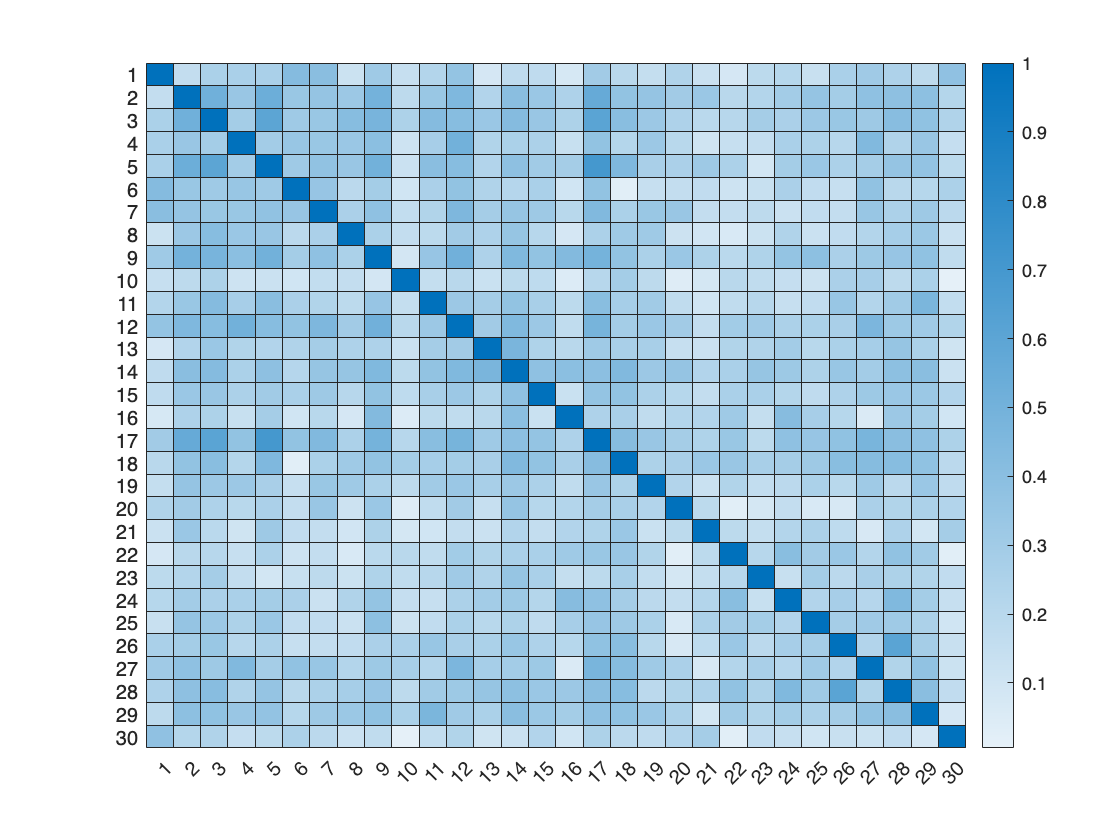

mean_returnsx=mean(returnsx);
Sigma = cov(returnsx);
C = corrcov(Sigma);
heatmap(C);

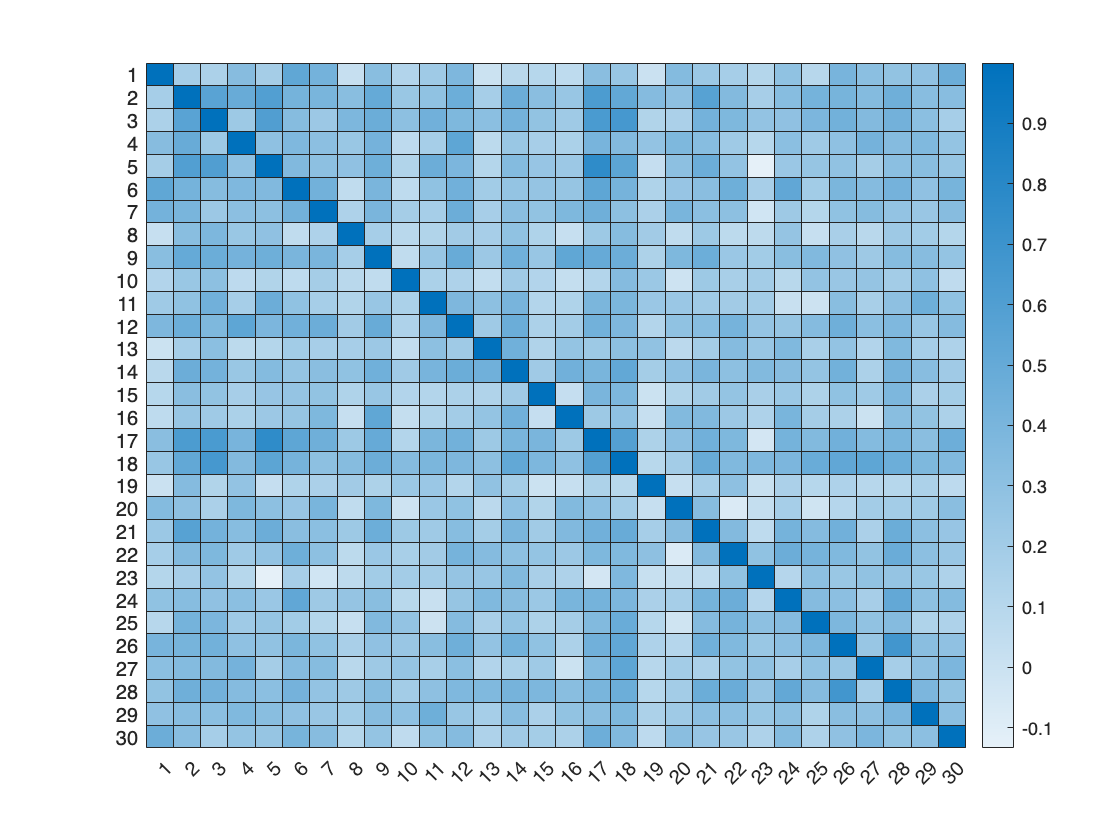

% Compute meand and covariances using first 100 data points
returnsx_1=returnsx(1:100,:);
mean_returnsx_1=mean(returnsx_1);
std_returnsx_1=std(returnsx_1);
Sigmax = cov(returnsx_1);
Cx = corrcov(Sigmax);
heatmap(Cx);

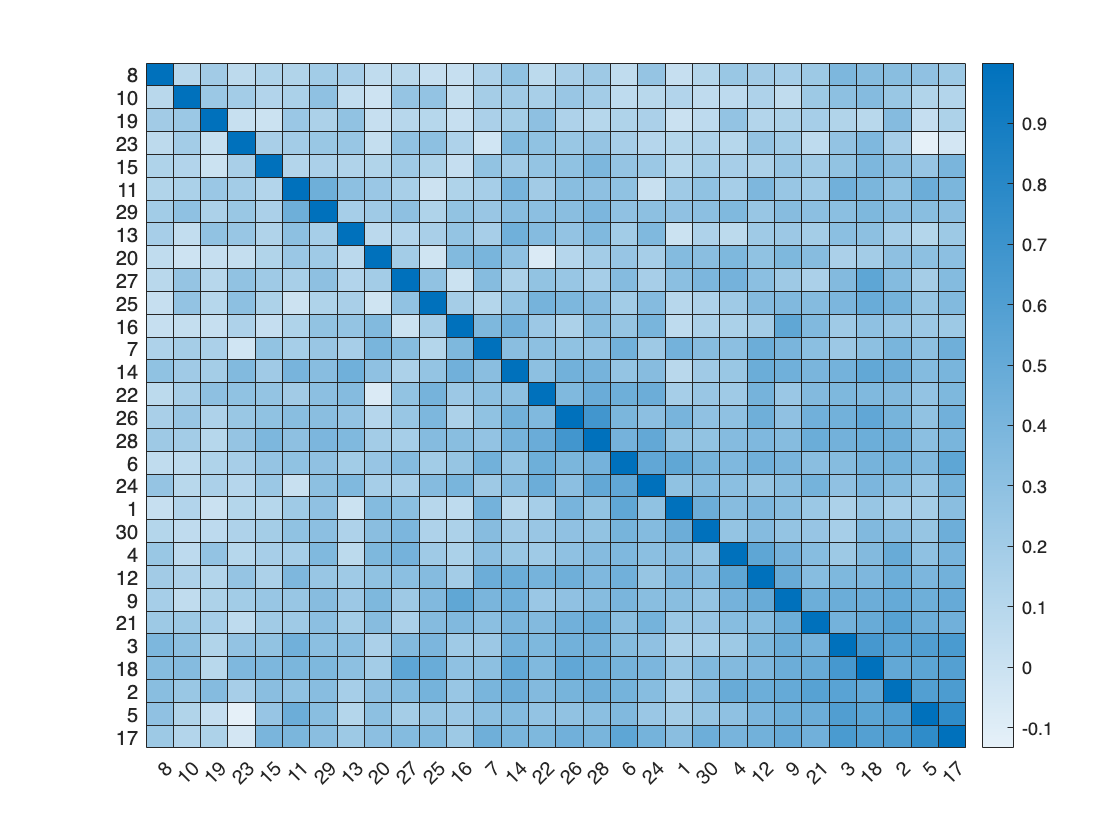

% Calculate weights of the risk parity portfolio by clustering by correlations
% Compute the correlation distance matrix
distCorr = ((1-Cx)/2).^0.5;
% Compute the linkage
link = linkage(distCorr);
% Sort assets for quasi-diagonalization 
nLeafNodes = size(link,1) + 1;
rootNodeId = 2*nLeafNodes - 1;
sortedIdx = getLeafNodesInGroup(rootNodeId,link);
heatmap(Cx(sortedIdx,sortedIdx), XData=sortedIdx, YData=sortedIdx);

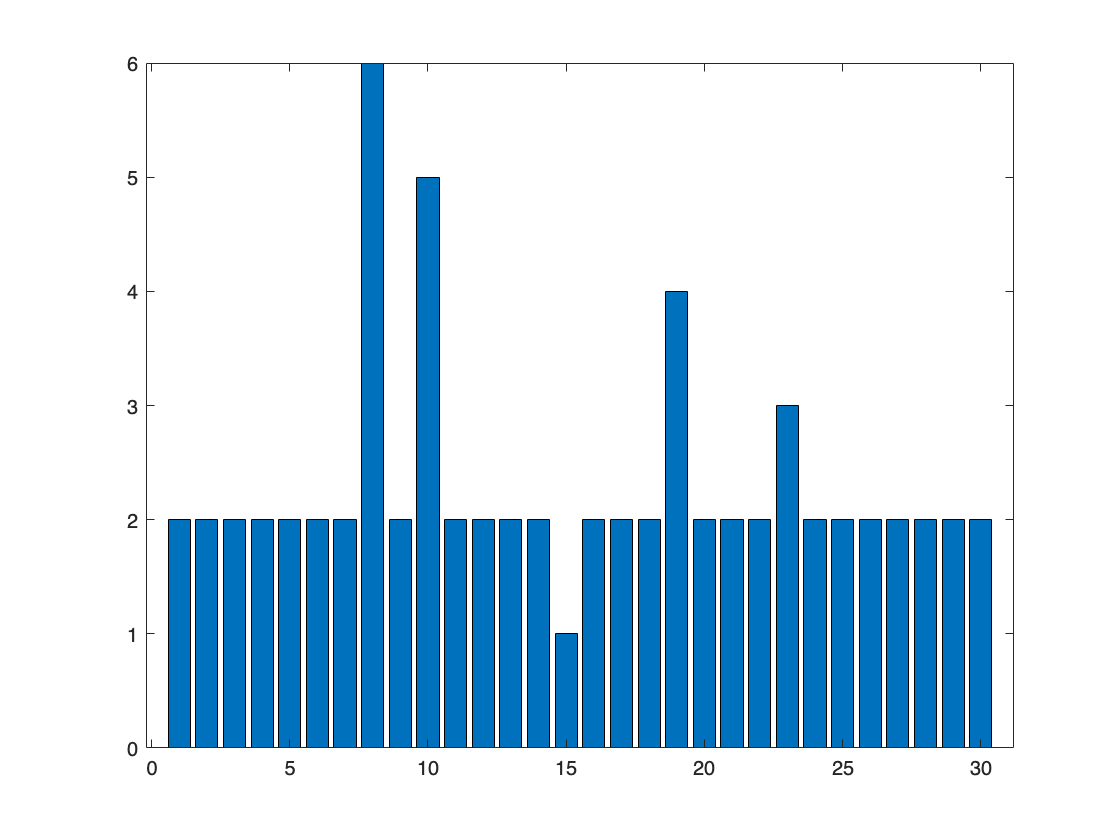

% Get clusters
Tx = cluster(link, MaxClust=6);
% Assets in each cluster (asset 5 is in cluster 2 and so on)
bar(Tx)

% Compute RP portfolio
wHRP = hrpPortfolio(Tx,Sigma)

wHRP =     0.0083
    0.0117
    0.0103
    0.0083
    0.0109
    0.0070
    0.0111
    0.1729
    0.0122
    0.0878


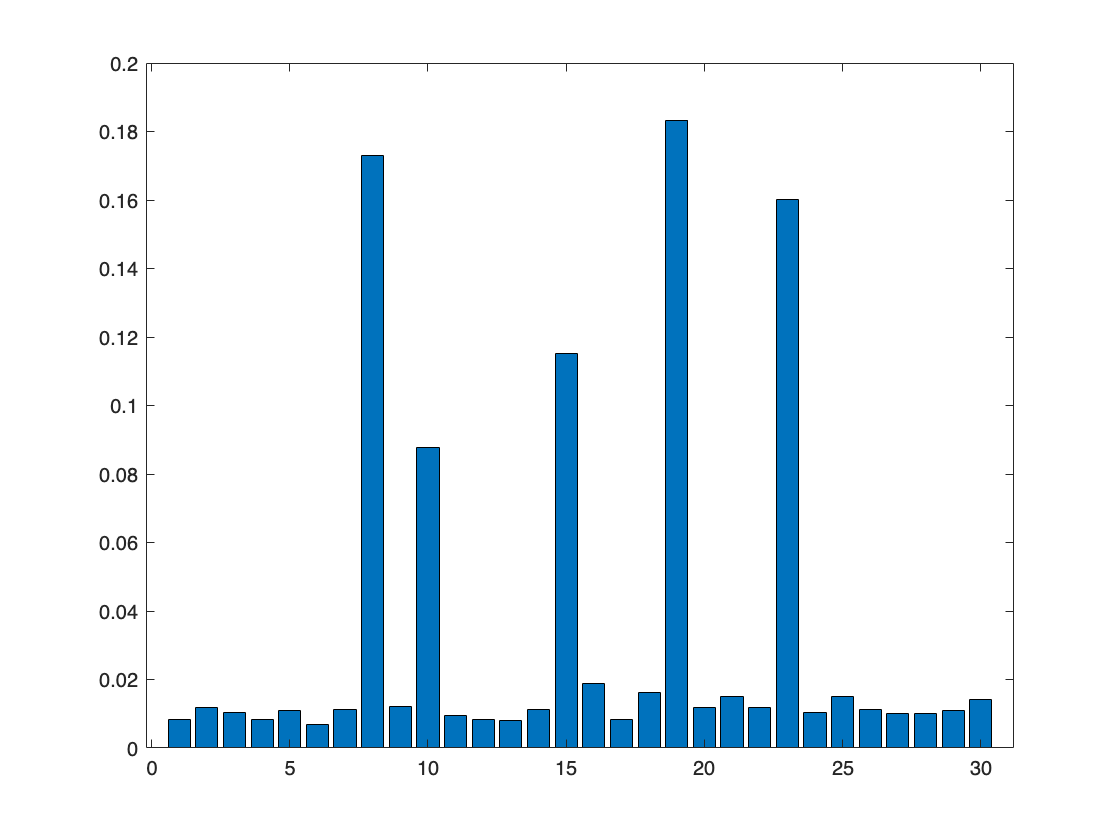

% Weights Risk Parity Portfolio
bar(wHRP)

% Compute meand and covariances using the second 150 data points
returnsx_2=returnsx(101:250,:);
mean_returnsx_2=mean(returnsx_2);
std_returnsx_2=std(returnsx_2);
Sigmax2 = cov(returnsx_2);

% Build the RP portfolio using the weights in wHRP

**In-sample HRP**

p = Portfolio;
p = Portfolio(p, 'LowerBound', zeros(size(mean_returnsx_1))); % Do Not Allow short positions
p = Portfolio(p, 'LowerBudget', 1, 'UpperBudget', 1);
p = Portfolio(p, 'AssetMean', mean_returnsx_1, 'AssetCovar', Sigmax);

% Compute in-sample performance for the RP portfolio
[risk_in_RP, ret_in_RP] = estimatePortMoments(p, wHRP)

risk_in_RP = 0.0068

ret_in_RP = 3.1302e-04

**Out-of-sample HRP**

pO = Portfolio;
pO = Portfolio(pO, 'LowerBound', zeros(size(mean_returnsx_2))); % Do Not Allow short positions
pO = Portfolio(pO, 'LowerBudget', 1, 'UpperBudget', 1);
pO = Portfolio(pO, 'AssetMean', mean_returnsx_2, 'AssetCovar', Sigmax2);

% Compute out-of-sample performance for the RP portfolio
[risk_out_RP, ret_out_RP] = estimatePortMoments(pO, wHRP)

risk_out_RP = 0.0069

ret_out_RP = 9.4842e-04

**In-sample EW**

nassets=length(mean_returnsx_1);
% Equal weights to all assets
wEW=((1/nassets)*(ones(nassets, 1)));

[risk_in_EW, ret_in_EW] = estimatePortMoments(p, wEW)  % mean and std

risk_in_EW = 0.0060

ret_in_EW = 5.7617e-04

**Out-of-sample EW**

[risk_out_EW, ret_out_EW] = estimatePortMoments(pO, wEW)  % mean and std

risk_out_EW = 0.0056

ret_out_EW = 7.9580e-04

% Sharpe Ratio Calculation
% Sharpe Ratios for in-sample and out-sample
Sharpe_in_RP = (ret_in_RP) / risk_in_RP;
Sharpe_out_RP = (ret_out_RP) / risk_out_RP;

Sharpe_EW_in = (ret_in_EW) / risk_in_EW;
Sharpe_EW_out = (ret_out_EW) / risk_out_EW;

% T-test for Sharpe Ratio
% Assuming n is the number of observations
n_in = length(returnsx_1);  % replace with the actual number of observations
n_out = length(returnsx_2);  % replace with the actual number of observations

% T-statistics for in-sample and out-sample
t_Sharpe_in_RP = Sharpe_in_RP * sqrt(n_in);
t_Sharpe_out_RP = Sharpe_out_RP * sqrt(n_out);

t_Sharpe_EW_in = Sharpe_EW_in * sqrt(n_in);
t_Sharpe_EW_out = Sharpe_EW_out * sqrt(n_out);

% P-value calculation
p_value_in_RP = 2 * (1 - tcdf(abs(t_Sharpe_in_RP), n_in - 1));
p_value_out_RP = 2 * (1 - tcdf(abs(t_Sharpe_out_RP), n_out - 1));

p_value_EW_in = 2 * (1 - tcdf(abs(t_Sharpe_EW_in), n_in - 1));
p_value_EW_out = 2 * (1 - tcdf(abs(t_Sharpe_EW_out), n_out - 1));

% Display the Sharpe Ratios and p-values
disp('Sharpe Ratios and p-values:');

Sharpe Ratios and p-values:


disp(['Sharpe In RP: ', num2str(Sharpe_in_RP), ' | p-value: ', num2str(p_value_in_RP)]);

Sharpe In RP: 0.045718 | p-value: 0.64854


disp(['Sharpe Out RP: ', num2str(Sharpe_out_RP), ' | p-value: ', num2str(p_value_out_RP)]);

Sharpe Out RP: 0.13801 | p-value: 0.093056


disp(['Sharpe EW In: ', num2str(Sharpe_EW_in), ' | p-value: ', num2str(p_value_EW_in)]);

Sharpe EW In: 0.096049 | p-value: 0.33915


disp(['Sharpe EW Out: ', num2str(Sharpe_EW_out), ' | p-value: ', num2str(p_value_EW_out)]);

Sharpe EW Out: 0.14298 | p-value: 0.081976


### Market Timing Strategies

As an illustration, here we use only two of the 30 DJI component stocks, AA and CAT.

T = readtable('dowPortfolio.xlsx');
symbols = ["AA", "CAT", "IBM", "JNJ", "XOM"]

symbols = 1×5 string array
    "AA"    "CAT"    "IBM"    "JNJ"    "XOM"


Prune the table to hold only the dates and selected stocks.

timeColumn = "Dates";
T = T(:,[timeColumn symbols]);

Convert the data to a timetable.

pricesTT = table2timetable(T,'RowTimes','Dates');

View the structure of the prices timetable.

head(pricesTT)

       Dates        AA       CAT      IBM      JNJ      XOM 
    ___________    _____    _____    _____    _____    _____

    03-Jan-2006    28.72    55.86    80.13    59.08    56.64
    04-Jan-2006    28.89    57.29    80.03    59.99    56.74
    05-Jan-2006    29.12    57.29    80.56    59.74    56.45
    06-Jan-2006    29.02    58.43    82.96    60.01    57.57
    09-Jan-2006    29.37    59.49    81.76    60.38    57.54
    10-Jan-2006    28.44    59.25     82.1    60.49    57.99
    11-Jan-2006    28.05    59.28    82.19    59.91    58.38
    12-Jan-2006    27.68    60.13    81.61    59.63    57.77



## Inspect Data Set

Visualize the correlation and total return of each stock in the data set.  

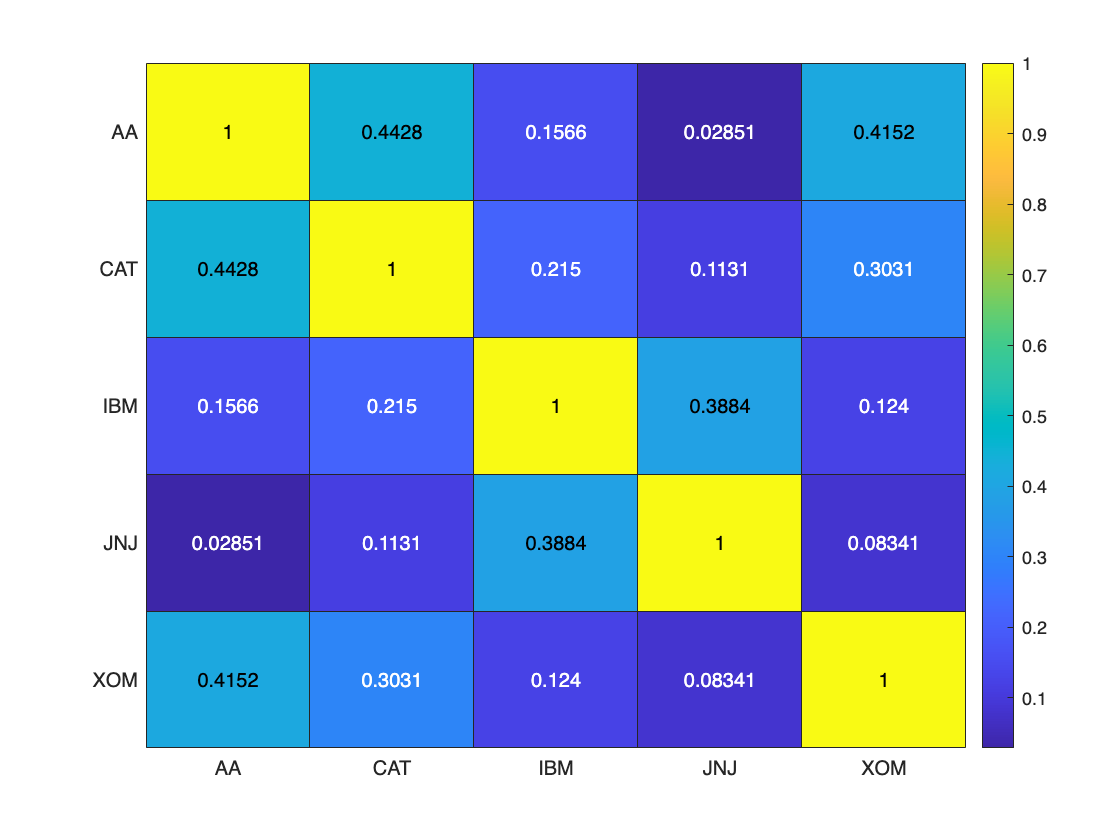

% Visualize the correlation between the stocks.
returns = tick2ret(pricesTT);
stockCorr = corr(returns.Variables);
heatmap(symbols,symbols,stockCorr,'Colormap',parula);

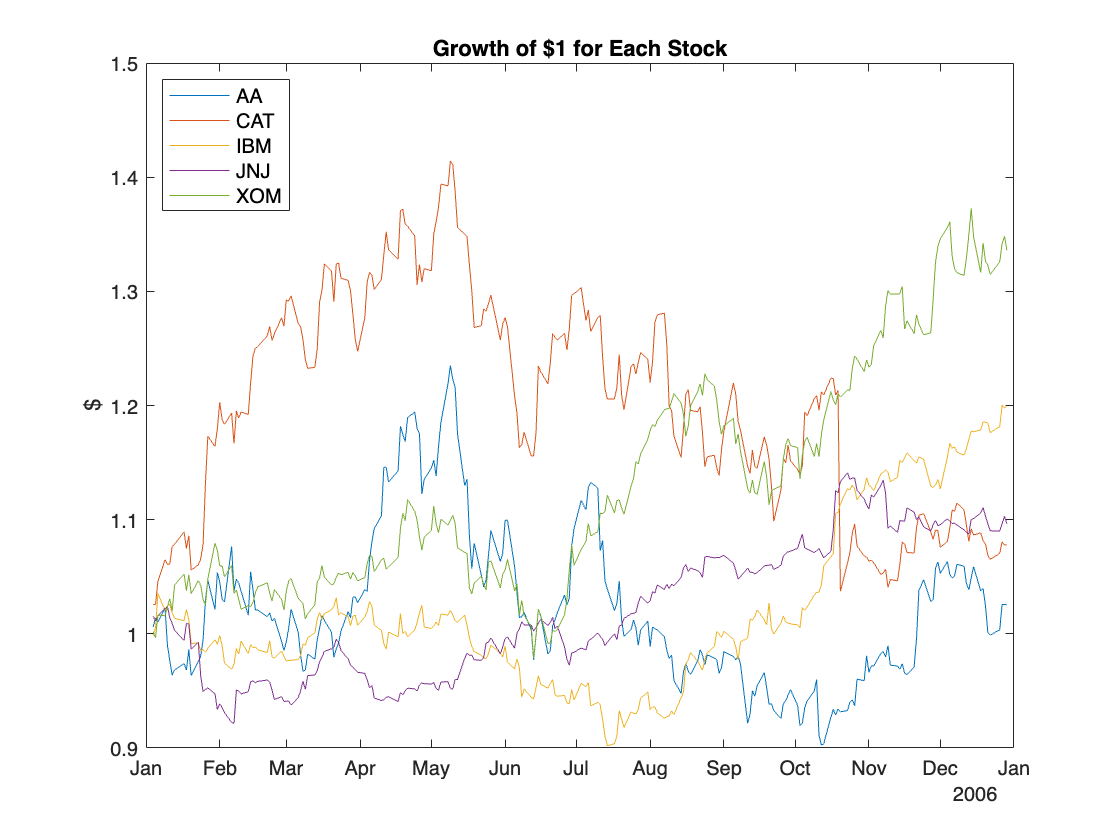

% Visualize the performance of each stock over the range of price data.
totalRet = ret2tick(returns);
plot(totalRet.Dates,totalRet.Variables);
legend(symbols,'Location','NW', 'FontSize', 10);
title('Growth of $1 for Each Stock')
ylabel('$')

% Get the total return of each stock for the duration of the data set.
totalRet(end,:)

ans = 1×5 timetable
       Dates         AA       CAT       IBM       JNJ       XOM 
    ___________    ______    ______    ______    ______    _____

    29-Dec-2006    1.0254    1.0781    1.1998    1.0965    1.336


## Build Signal Table

In addition to the historical adjusted asset prices, the backtesting framework allows you to optionally specify *signal* data when running a backtest.  The "time" dimension of the *signal* timetable must match that of the *prices* timetable — that is, the rows of each table must have matching datetime values for the `Time` column. 

This example builds a signal timetable to support each of the four market timing investment strategies:

- Simple moving average crossover (SMA) strategy

- Moving Average Convergence / Divergence (MACD) strategy

- Relative Strength Index (RSI) strategy

- GI Index

Each strategy has a timetable of signals that are precomputed. Before you run the backtest, you merge the four separate signal timetables into a single aggregate signal timetable to use for the backtest.

## SMA: Simple Moving Average Crossover

The SMA indicator uses 5-day and 20-day simple moving averages to make buy and sell decisions. When the 5-day SMA crosses the 20-day SMA (moving upwards), then the stock is bought. When the 5-day SMA crosses below the 20-day SMA, the stock is sold.

% Create SMA timetables using the movavg function.
sma5  = movavg(pricesTT,'simple',5);
sma20 = movavg(pricesTT,'simple',20);

Create the SMA indicator signal timetable.

smaSignalNameEnding = '_SMA5over20';

smaSignal = timetable;
for i = 1:numel(symbols)
    symi = symbols(i);
    % Build a timetable for each symbol, then aggregate them together.
    smaSignali = timetable(pricesTT.Dates,...
        double(sma5.(symi) > sma20.(symi)),...
        'VariableNames',{sprintf('%s%s',symi,smaSignalNameEnding)});
    % Use the synchronize function to merge the timetables together.
    smaSignal = synchronize(smaSignal,smaSignali);
end

The SMA signal timetable contains an indicator with a value of `1` when the 5-day moving average is above the 20-day moving average for each asset, and a `0` otherwise. The column names for each stock indicator are [*stock symbol*]`SMA5over20`. The [backtestStrategy](docid:finance_ug.object_backtest_strategy) object makes trading decisions based on these crossover events. 

View the structure of the SMA signal timetable.

head(smaSignal)

       Time        AA_SMA5over20    CAT_SMA5over20    IBM_SMA5over20    JNJ_SMA5over20    XOM_SMA5over20
    ___________    _____________    ______________    ______________    ______________    ______________

    03-Jan-2006          0                0                 0                 0                 0       
    04-Jan-2006          0                0                 0                 0                 0       
    05-Jan-2006          0                0                 0                 0                 0       
    06-Jan-2006          0                0                 0                 0                 0       
    09-Jan-2006          0                0                 0                 0 

Plot the signal for CAT asset to preview the trading frequency.

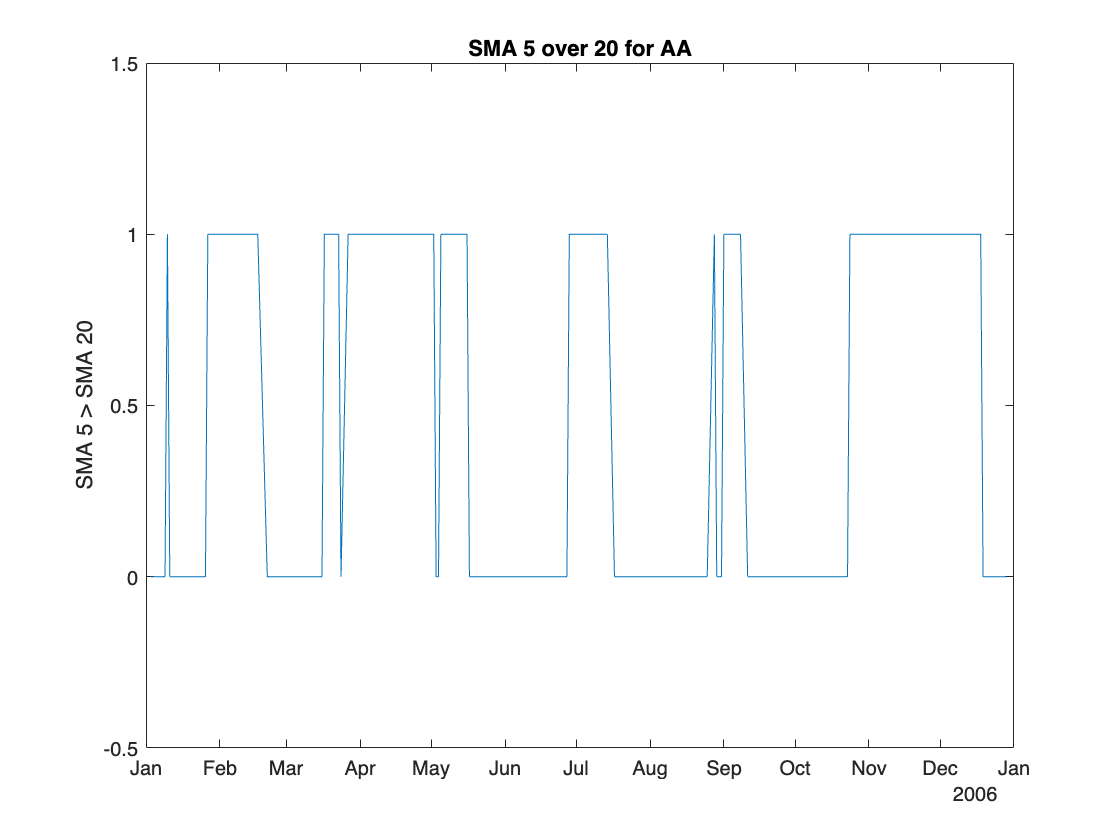

plot(smaSignal.Time,smaSignal.AA_SMA5over20);
ylim([-0.5, 1.5]);
ylabel('SMA 5 > SMA 20');
title(sprintf('SMA 5 over 20 for AA'));

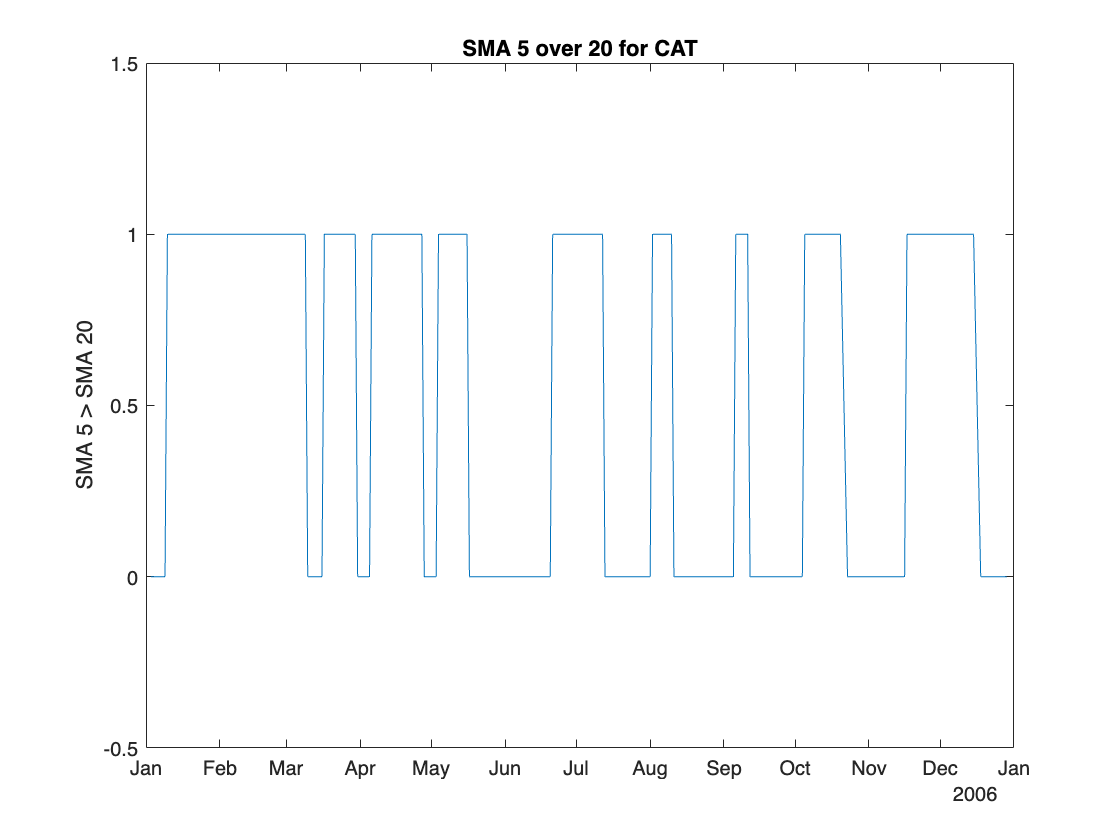


plot(smaSignal.Time,smaSignal.CAT_SMA5over20);
ylim([-0.5, 1.5]);
ylabel('SMA 5 > SMA 20');
title(sprintf('SMA 5 over 20 for CAT'));

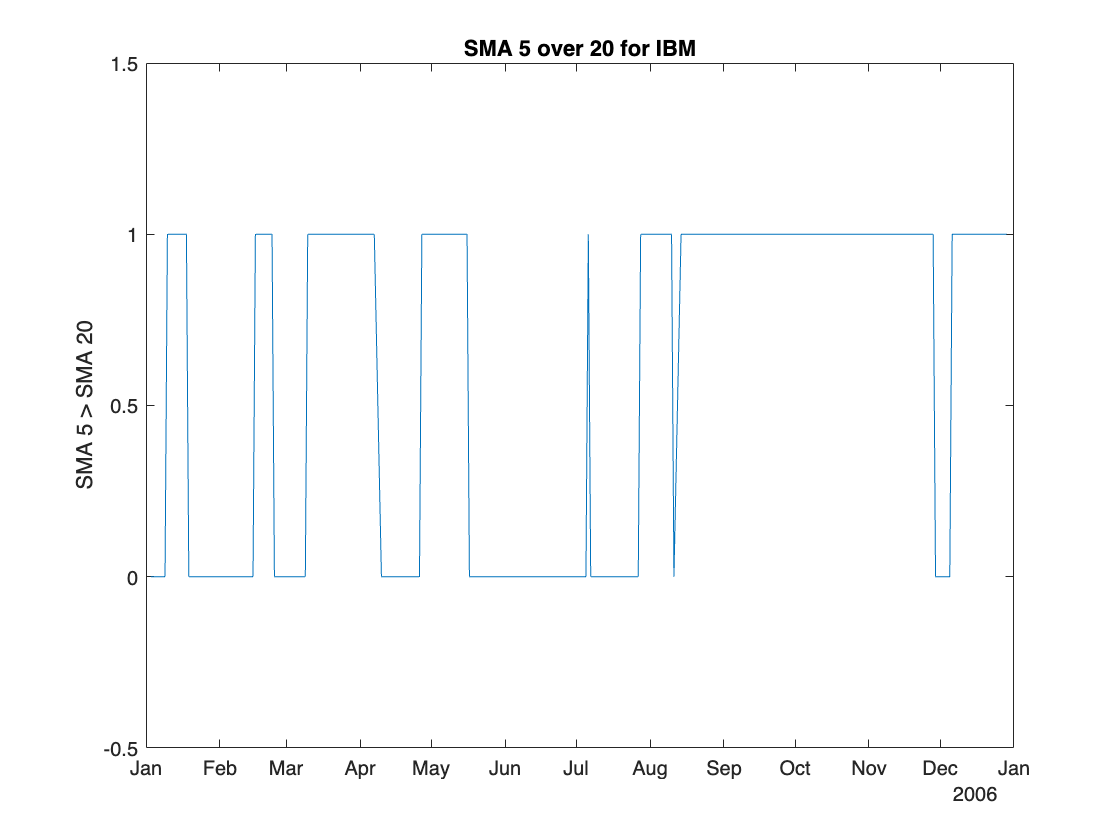


plot(smaSignal.Time,smaSignal.IBM_SMA5over20);
ylim([-0.5, 1.5]);
ylabel('SMA 5 > SMA 20');
title(sprintf('SMA 5 over 20 for IBM'));

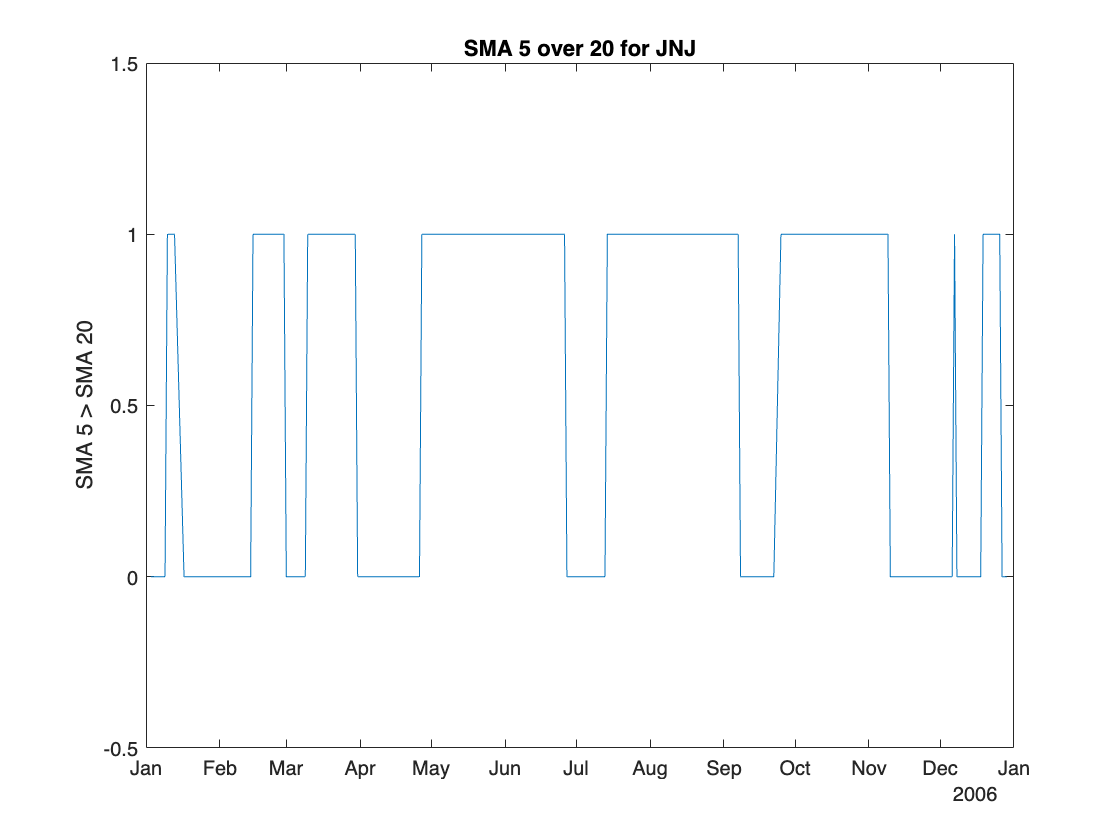


plot(smaSignal.Time,smaSignal.JNJ_SMA5over20);
ylim([-0.5, 1.5]);
ylabel('SMA 5 > SMA 20');
title(sprintf('SMA 5 over 20 for JNJ'));

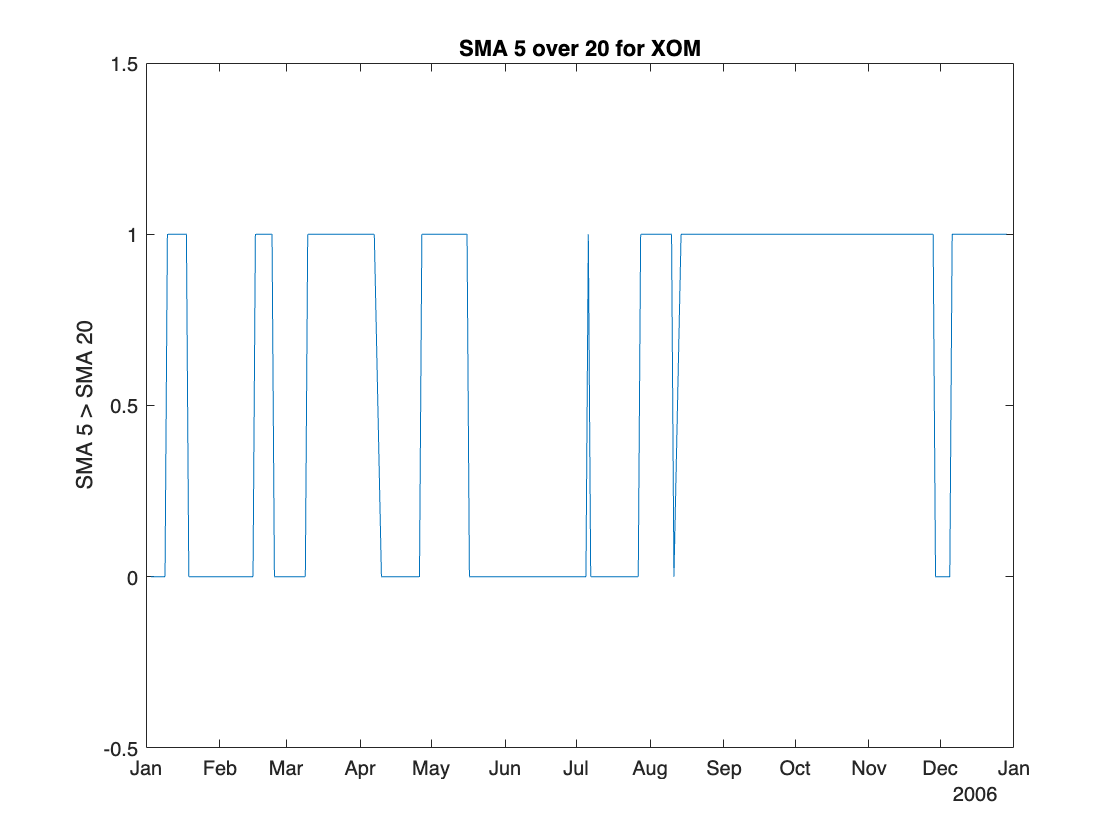


plot(smaSignal.Time,smaSignal.IBM_SMA5over20);
ylim([-0.5, 1.5]);
ylabel('SMA 5 > SMA 20');
title(sprintf('SMA 5 over 20 for XOM'));

## MACD: Moving Average Convergence/Divergence

You can use the MACD metric in a variety of ways. Often, MACD is compared to its own exponential moving average, but for this example, MACD serves as a trigger for a buy signal when the MACD rises above `0`. A position is sold when the MACD falls back below `0`.

% Create a timetable of the MACD metric using the MACD function.
macdTT = macd(pricesTT);

Create the MACD indicator signal timetable.

macdSignalNameEnding = '_MACD';

macdSignal = timetable;
for i = 1:numel(symbols)
    symi = symbols(i);
    % Build a timetable for each symbol, then aggregate the symbols together.
    macdSignali = timetable(pricesTT.Dates,...
        double(macdTT.(symi) > 0),...
        'VariableNames',{sprintf('%s%s',symi,macdSignalNameEnding)});
    macdSignal = synchronize(macdSignal,macdSignali);
end

The MACD signal table contains a column for each asset with the name [*stock symbol*]`MACD`. Each signal has a value of `1` when the MACD of the stock is above `0`. The signal has a value of `0` when the MACD of the stock falls below `0`.

head(macdSignal)

       Time        AA_MACD    CAT_MACD    IBM_MACD    JNJ_MACD    XOM_MACD
    ___________    _______    ________    ________    ________    ________

    03-Jan-2006       0          0           0           0           0    
    04-Jan-2006       0          0           0           0           0    
    05-Jan-2006       0          0           0           0           0    
    06-Jan-2006       0          0           0           0           0    
    09-Jan-2006       0          0           0           0           0    
    10-Jan-2006       0          0           0           0           0    
    11-Jan-2006       0          0           0           0           0    
 

Similar to the SMA, plot the signal for CAT asset to preview the trading frequency.

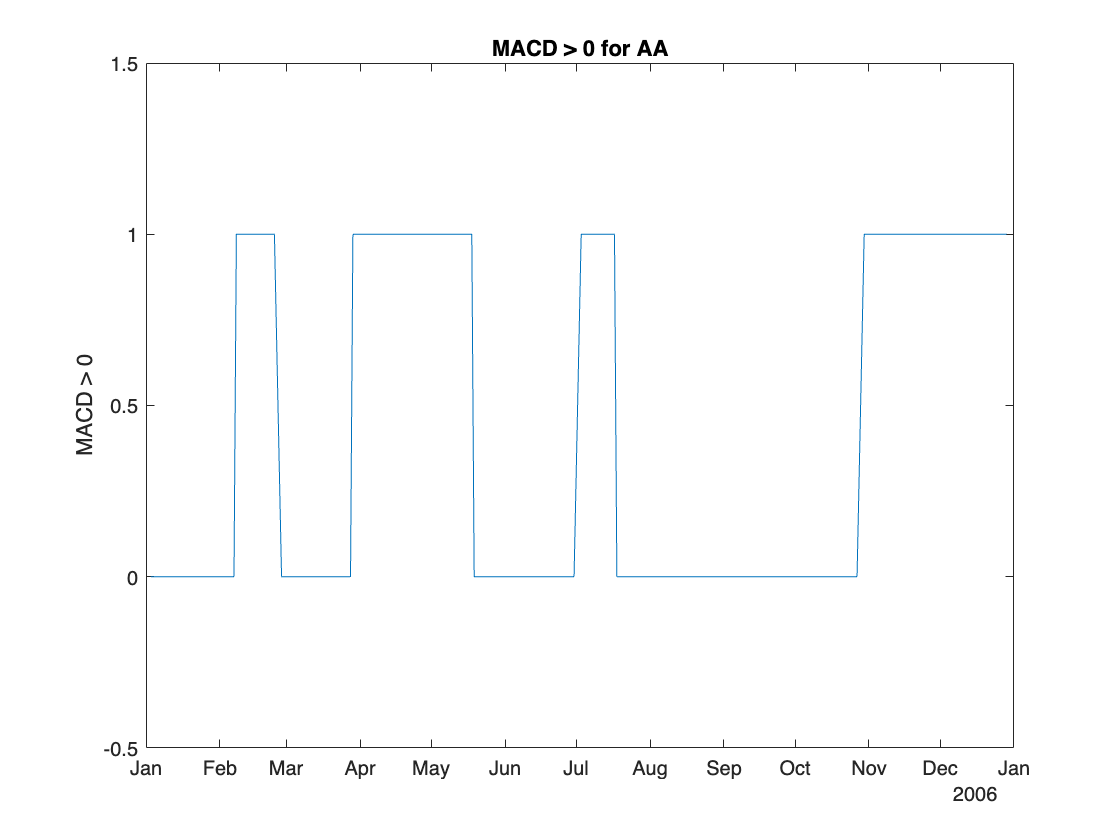

plot(macdSignal.Time,macdSignal.AA_MACD)
ylim([-0.5, 1.5]);
ylabel('MACD > 0');
title(sprintf('MACD > 0 for AA'));

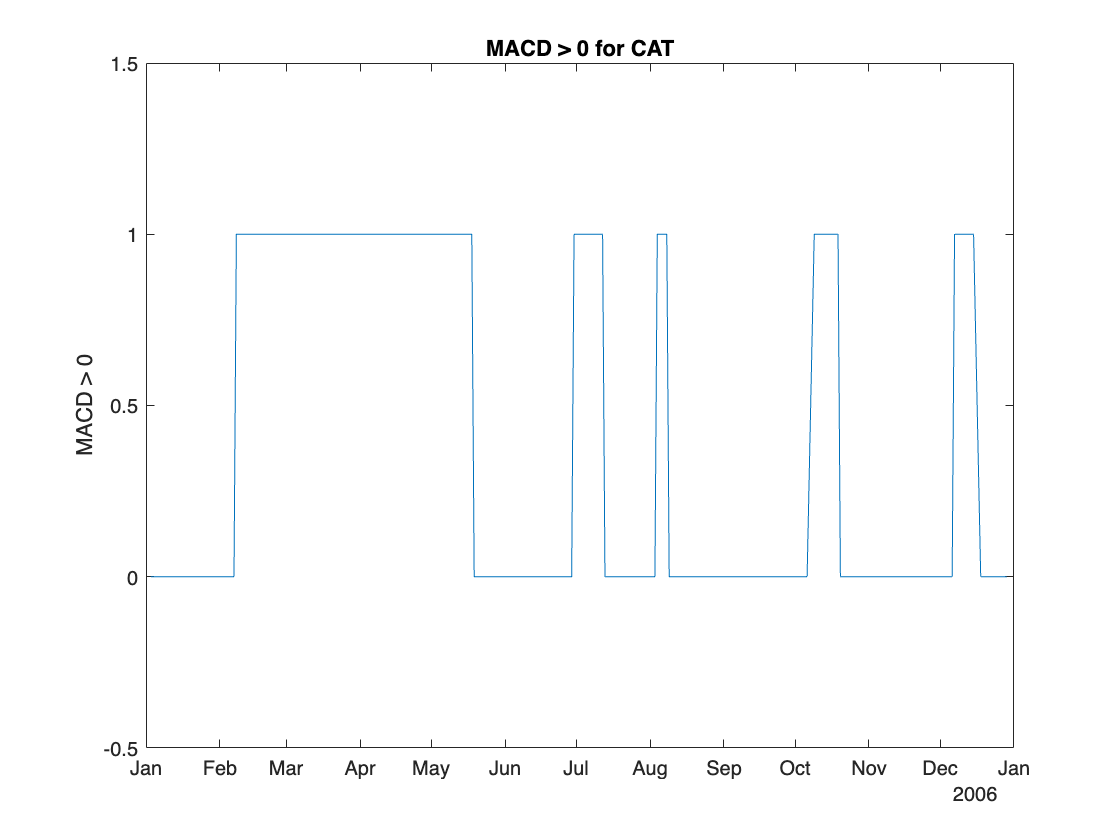


plot(macdSignal.Time,macdSignal.CAT_MACD)
ylim([-0.5, 1.5]);
ylabel('MACD > 0');
title(sprintf('MACD > 0 for CAT'));

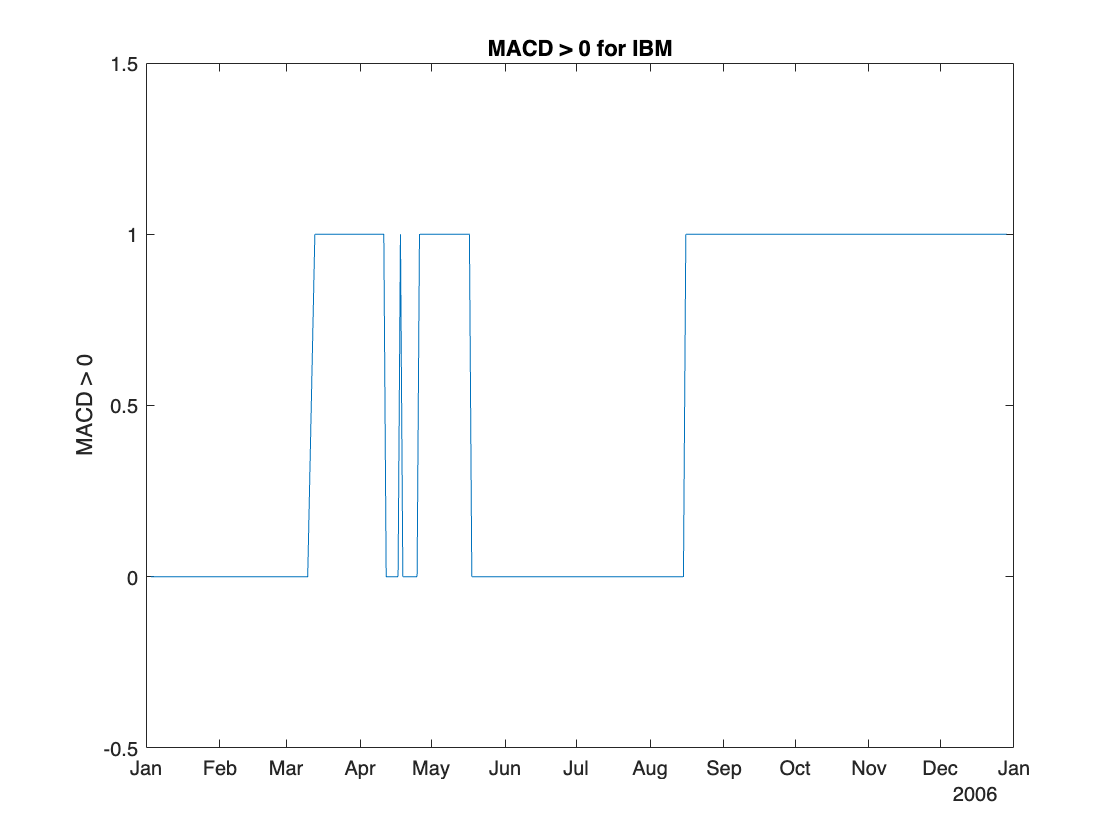


plot(macdSignal.Time,macdSignal.IBM_MACD)
ylim([-0.5, 1.5]);
ylabel('MACD > 0');
title(sprintf('MACD > 0 for IBM'));

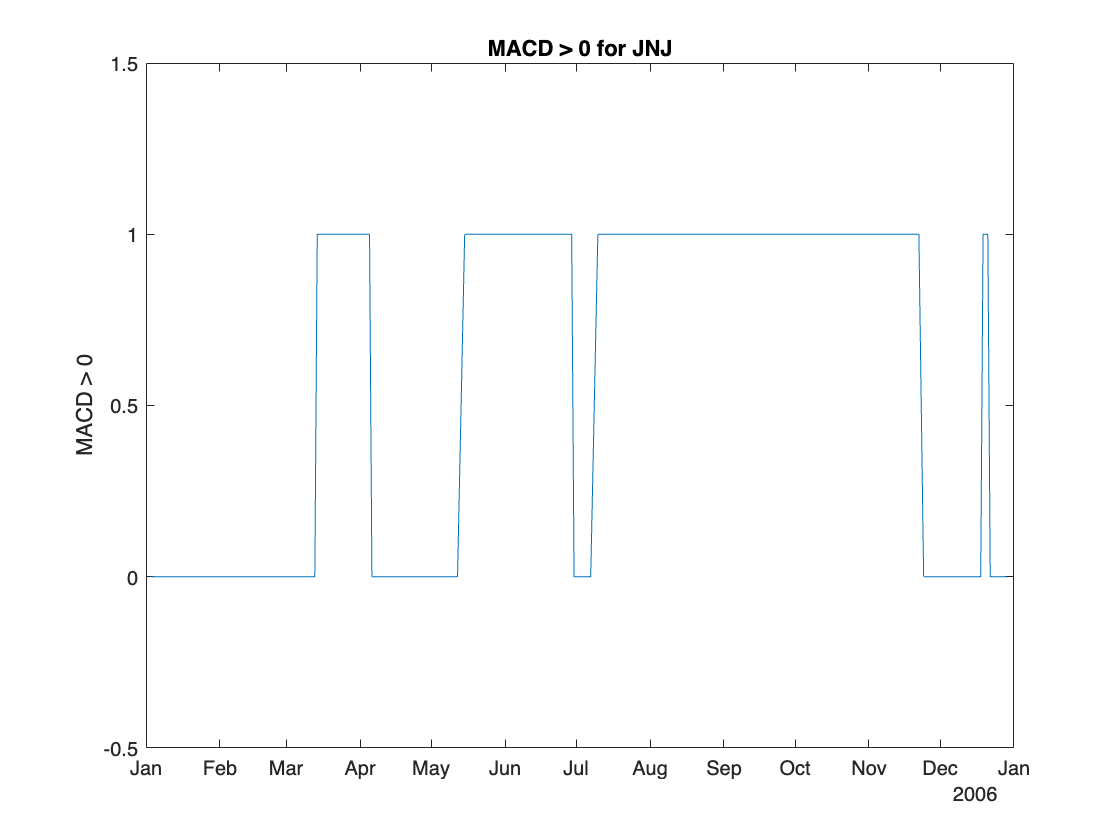


plot(macdSignal.Time,macdSignal.JNJ_MACD)
ylim([-0.5, 1.5]);
ylabel('MACD > 0');
title(sprintf('MACD > 0 for JNJ'));

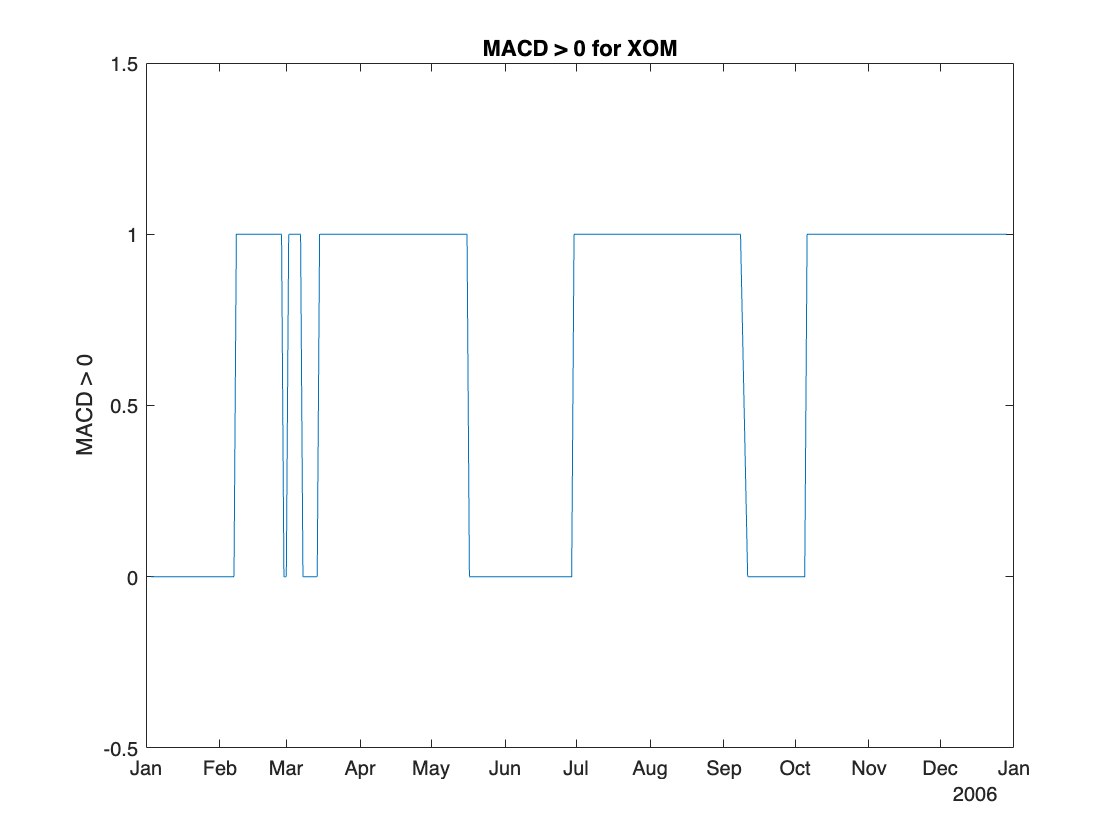


plot(macdSignal.Time,macdSignal.XOM_MACD)
ylim([-0.5, 1.5]);
ylabel('MACD > 0');
title(sprintf('MACD > 0 for XOM'));

## RSI: Relative Strength Index

The RSI is a metric to capture momentum. A common heuristic is to buy when the RSI falls below `30` and to sell when the RSI rises above `70`.

Window size is 14 days.

rsiSignalNameEnding = '_RSI';

rsiSignal = timetable;
for i = 1:numel(symbols)
    symi = symbols(i);
    rsiValues = rsindex(pricesTT.(symi));
    rsiBuySell = zeros(size(rsiValues));
    rsiBuySell(rsiValues < 30) = 1;
    rsiBuySell(rsiValues > 70) = -1;
    % Build a timetable for each symbol, then aggregate the symbols together.
    rsiSignali = timetable(pricesTT.Dates,...
        rsiBuySell,...
        'VariableNames',{sprintf('%s%s',symi,rsiSignalNameEnding)});
    rsiSignal = synchronize(rsiSignal,rsiSignali);
end

The RSI signal takes a value of `1` (indicating a buy signal) when the RSI value for the stock falls below `30`. The signal takes a value of `-1` (indicating a sell signal) when the RSI for the stock rises above `70`. Otherwise, the signal takes a value of `0`, indicating no action.

Plot the signal for a CAT asset to preview the trading frequency.

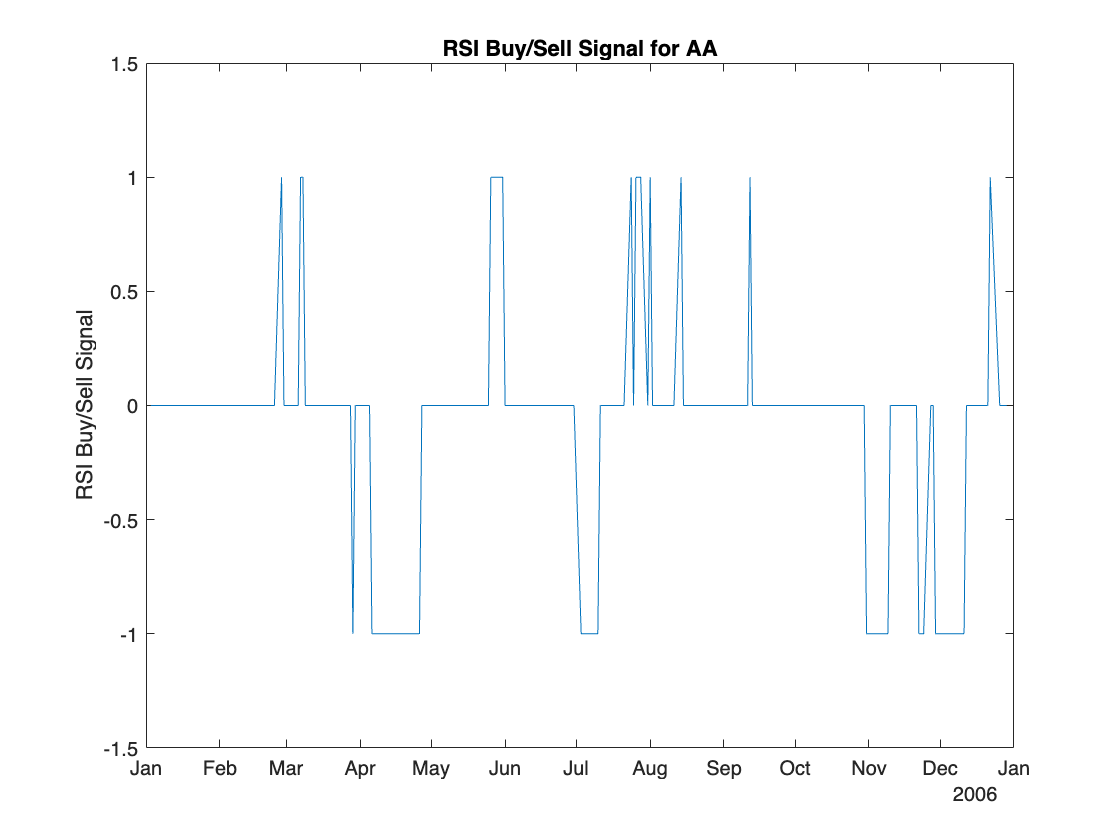

plot(rsiSignal.Time,rsiSignal.AA_RSI)
ylim([-1.5, 1.5]);
ylabel('RSI Buy/Sell Signal');
title(sprintf('RSI Buy/Sell Signal for AA'));

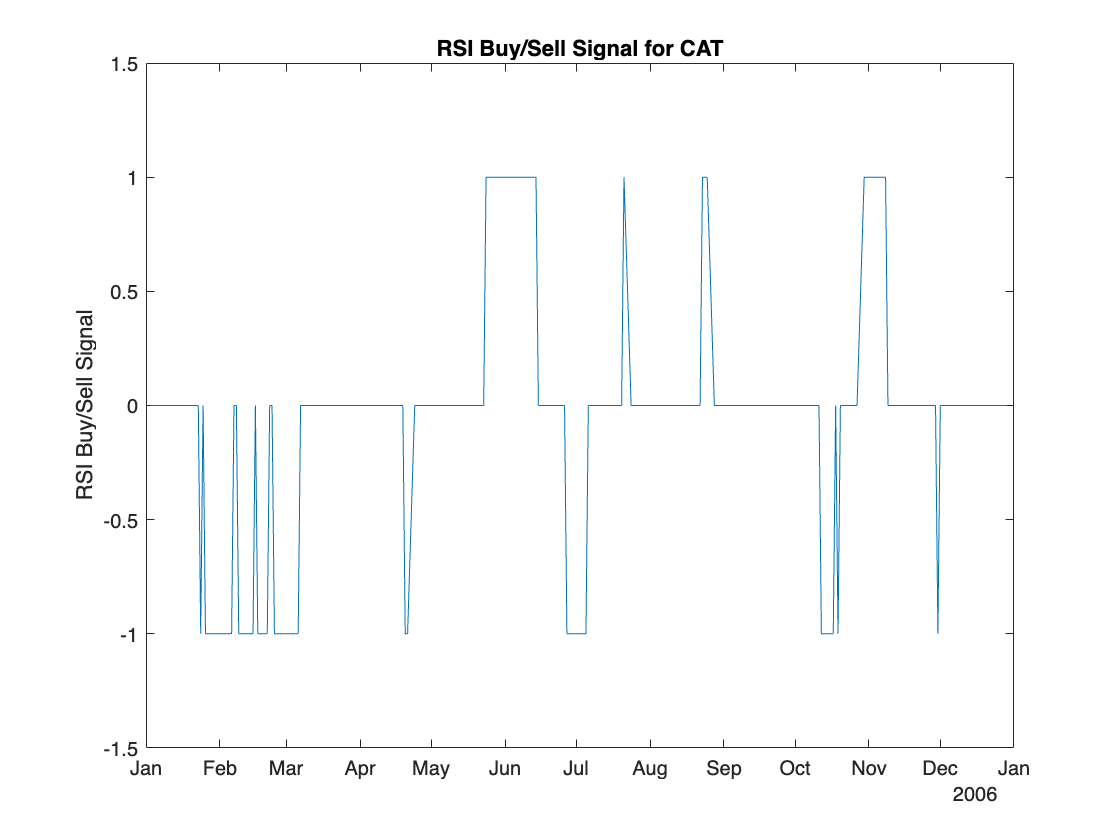


plot(rsiSignal.Time,rsiSignal.CAT_RSI)
ylim([-1.5, 1.5]);
ylabel('RSI Buy/Sell Signal');
title(sprintf('RSI Buy/Sell Signal for CAT'));

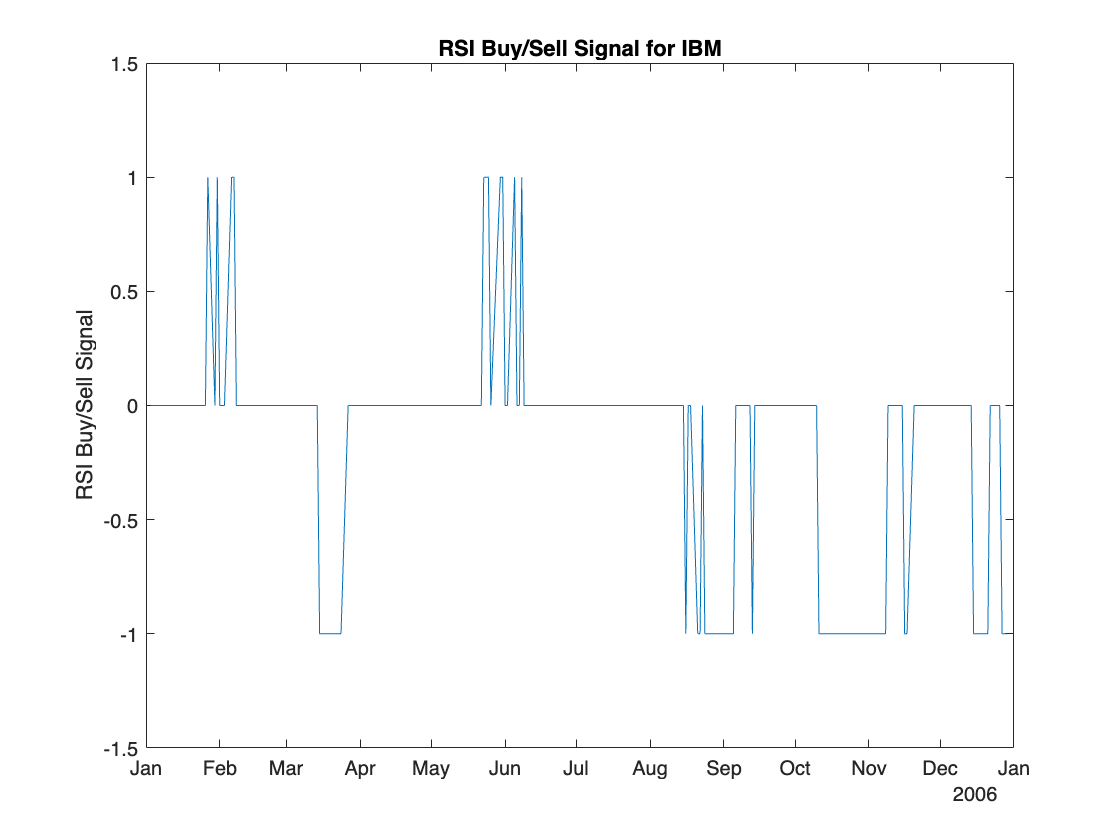


plot(rsiSignal.Time,rsiSignal.IBM_RSI)
ylim([-1.5, 1.5]);
ylabel('RSI Buy/Sell Signal');
title(sprintf('RSI Buy/Sell Signal for IBM'));

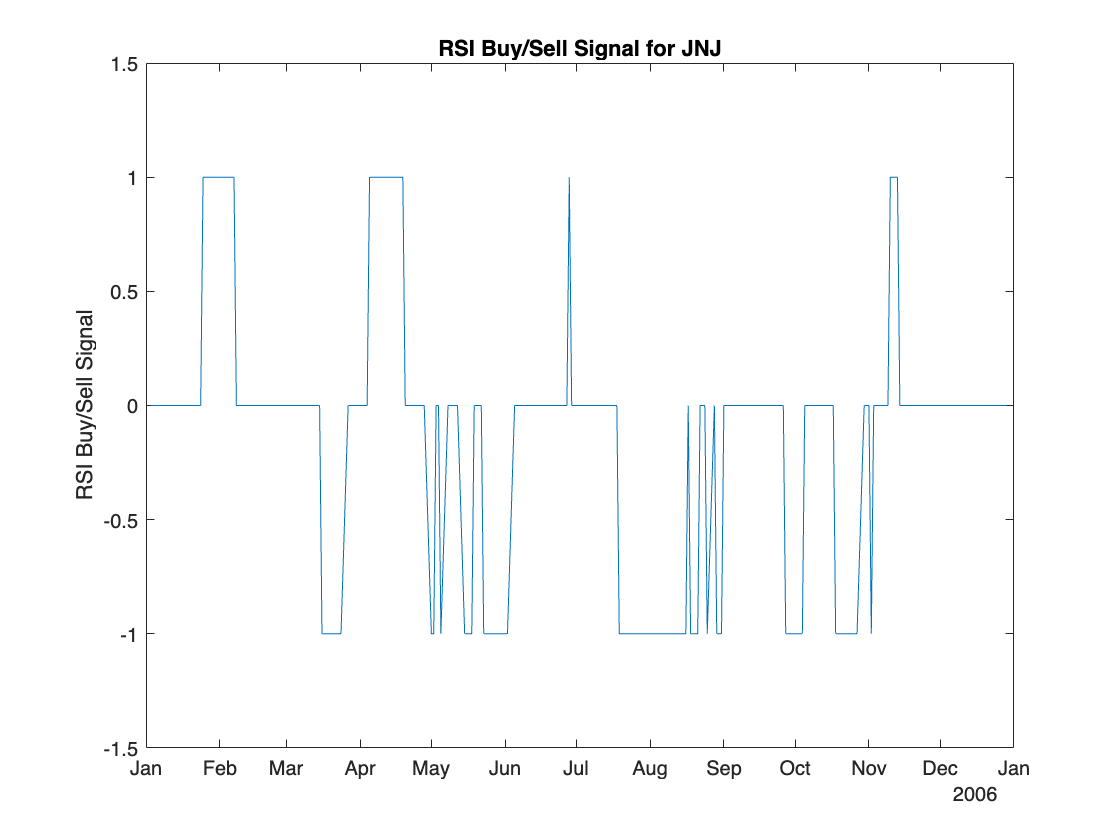


plot(rsiSignal.Time,rsiSignal.JNJ_RSI)
ylim([-1.5, 1.5]);
ylabel('RSI Buy/Sell Signal');
title(sprintf('RSI Buy/Sell Signal for JNJ'));

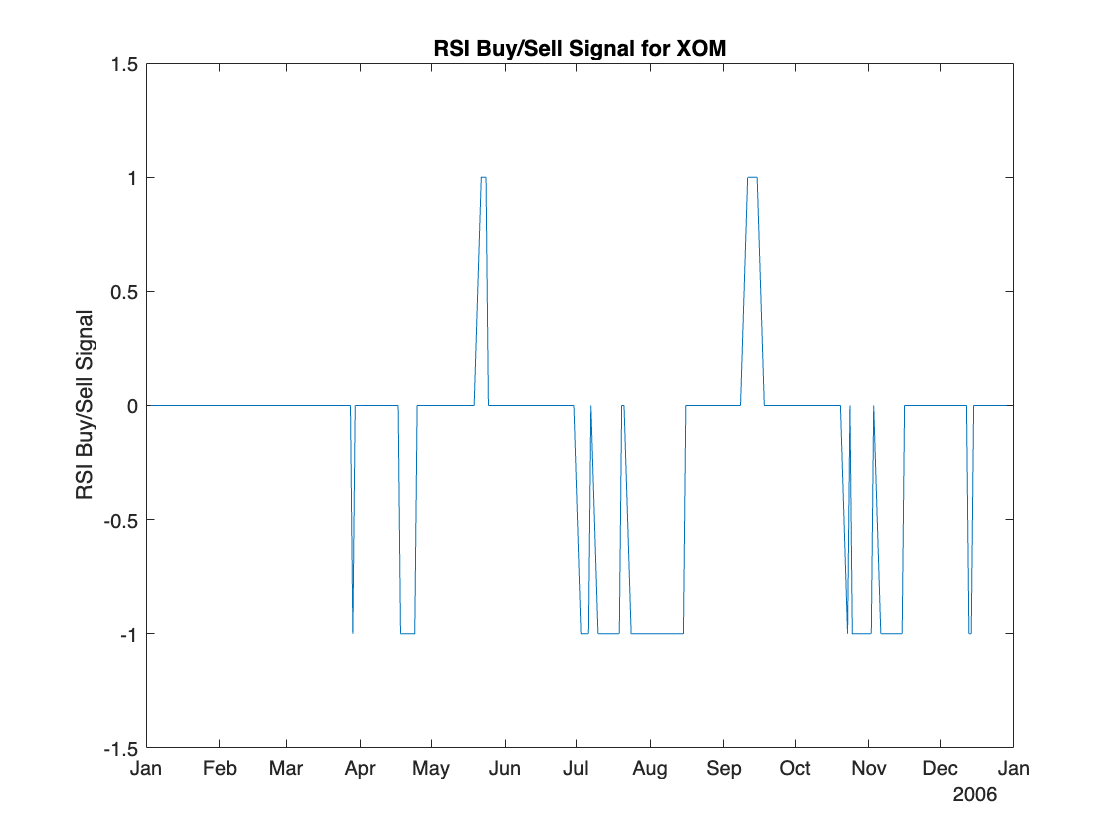


plot(rsiSignal.Time,rsiSignal.XOM_RSI)
ylim([-1.5, 1.5]);
ylabel('RSI Buy/Sell Signal');
title(sprintf('RSI Buy/Sell Signal for XOM'));

## GI Index: Goodness Indicator Index

The GI indicator uses SharpeRatio/sigma to make buy and sell decisions. When SR/sigma is above 0.5, then the stock is bought. When SR/sigma is below 0.5 the stock is sold.

% Create GI timetables 
x1=returns.Variables;
xt=pricesTT.Dates;
Data1=zeros(size(pricesTT));
Data1(2:end,:)=x1;
% Window size for GI computation
Wsize=10;
[mu1,sigma1,srat1,gi1]=RollinWindow(Data1,Wsize);
pTT=zeros(size(pricesTT));
startx= Wsize;
pTT(startx:end,:)=gi1;
sss=size(pTT);
pTT(1:startx,:)=mean(gi1).*ones(startx,sss(1,2));
GITT = array2timetable(pTT,'VariableNames',symbols,'RowTimes',xt)

GITT = 251×5 timetable
       Time          AA         CAT        IBM        JNJ       XOM  
    ___________    _______    _______    _______    _______    ______

    03-Jan-2006     3.4066     3.1163     13.154     13.112    17.652
    04-Jan-2006     3.4066     3.1163     13.154     13.112    17.652
    05-Jan-2006     3.4066     3.1163     13.154     13.112    17.652
    06-Jan-2006     3.4066     3.1163     13.154     13.112    17.652
    09-Jan-2006     3.4066     3.1163     13.154     13.112    17.652
    10-Jan-2006     3.4066     3.1163     13.154     13.112    17.652
    11-Jan-2006     3.4066     3.1163     13.154     13.112    17.652
    12-Jan-2006

#### Create the GI indicator signal timetable.

GISignalNameEnding = '_GI';

GISignal = timetable;
for i = 1:numel(symbols)
    symi = symbols(i);
    % Build a timetable for each symbol, then aggregate them together.
    GISignali = timetable(pricesTT.Dates,...
        double(GITT.(symi) > 0.5),...
        'VariableNames',{sprintf('%s%s',symi,GISignalNameEnding)});
    % Use the synchronize function to merge the timetables together.
    GISignal = synchronize(GISignal,GISignali);
end

The GI signal timetable contains an indicator with a value of `1` when SR/sigma is above 0.5, and a `0` otherwise. 

View the structure of the GI signal timetable.

head(GISignal)

       Time        AA_GI    CAT_GI    IBM_GI    JNJ_GI    XOM_GI
    ___________    _____    ______    ______    ______    ______

    03-Jan-2006      1        1         1         1         1   
    04-Jan-2006      1        1         1         1         1   
    05-Jan-2006      1        1         1         1         1   
    06-Jan-2006      1        1         1         1         1   
    09-Jan-2006      1        1         1         1         1   
    10-Jan-2006      1        1         1         1         1   
    11-Jan-2006      1        1         1         1         1   
    12-Jan-2006      1        1         1         1         1   



Plot the signal for CAT asset to preview the trading frequency.

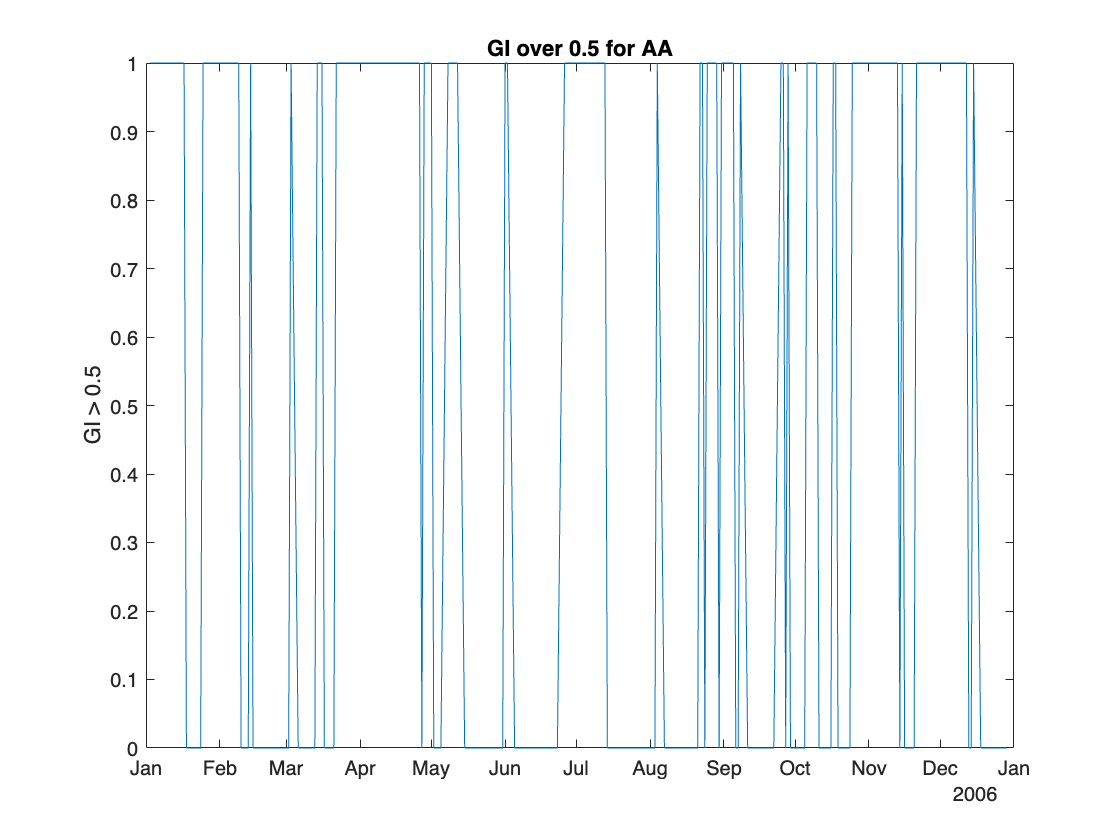

plot(GISignal.Time,GISignal.AA_GI)
ylabel('GI > 0.5')
title(sprintf('GI over 0.5 for AA'))

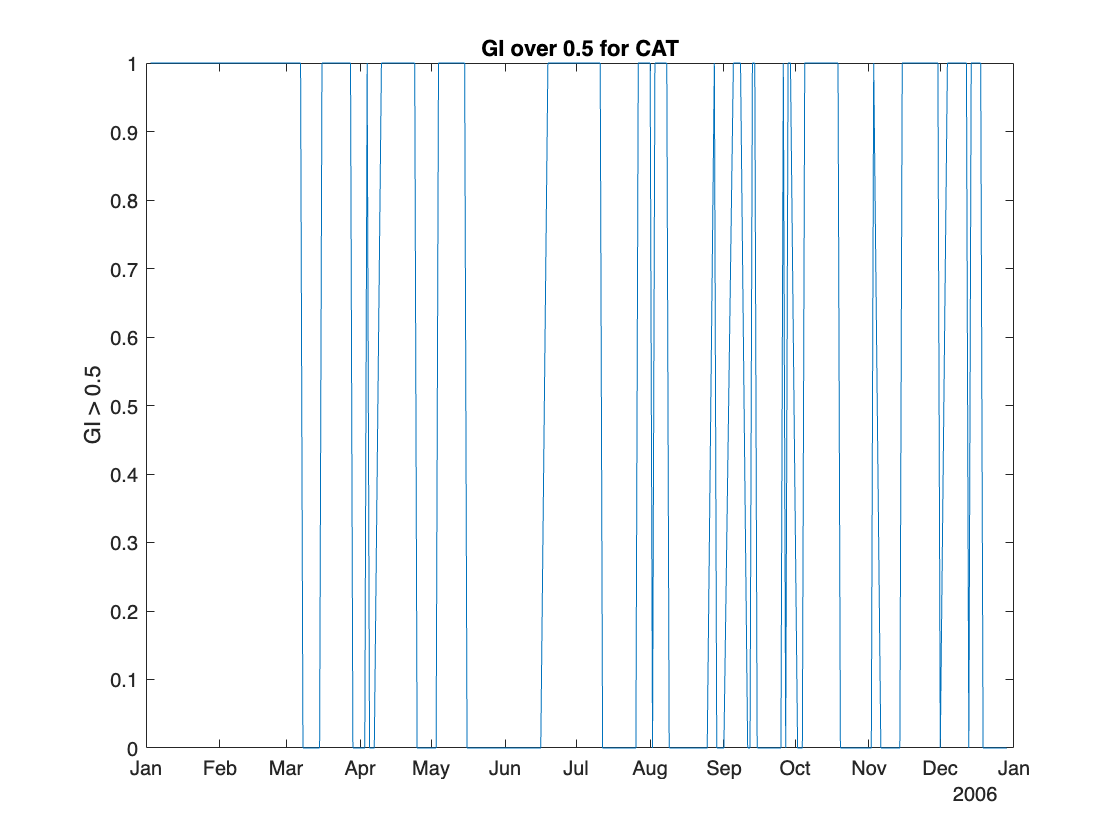


plot(GISignal.Time,GISignal.CAT_GI)
ylabel('GI > 0.5')
title(sprintf('GI over 0.5 for CAT'))

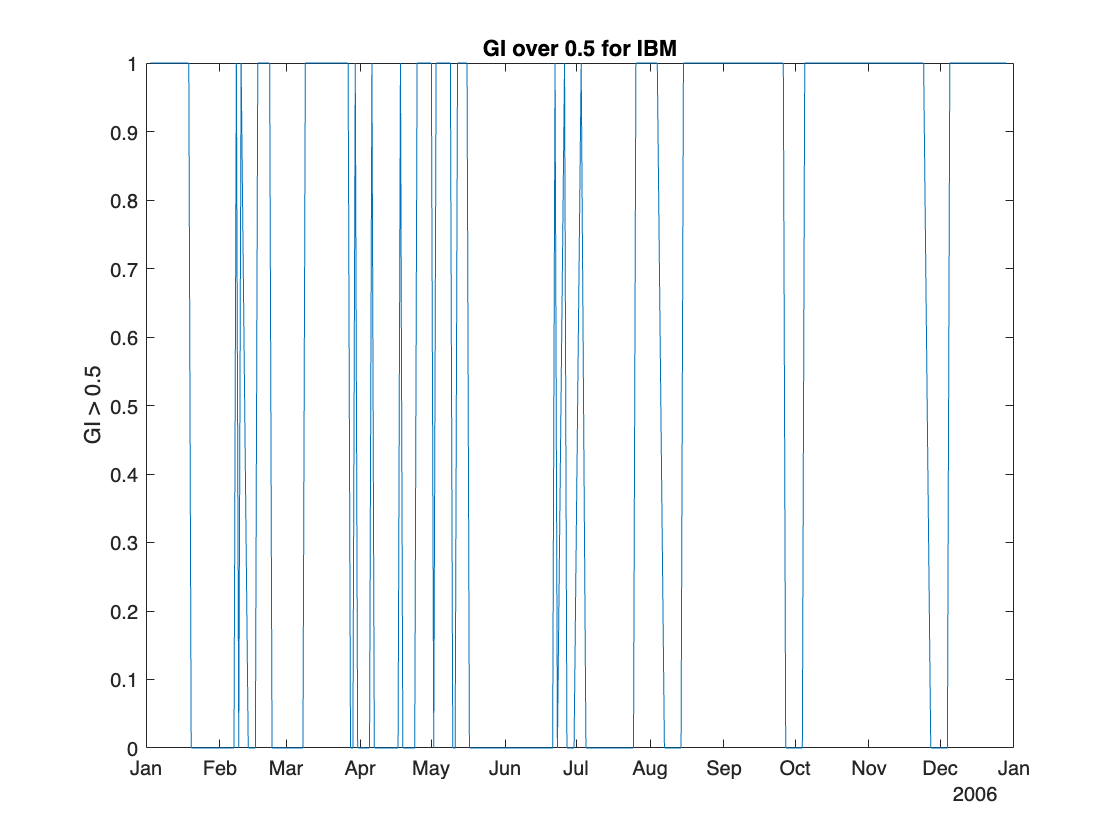


plot(GISignal.Time,GISignal.IBM_GI)
ylabel('GI > 0.5')
title(sprintf('GI over 0.5 for IBM'))

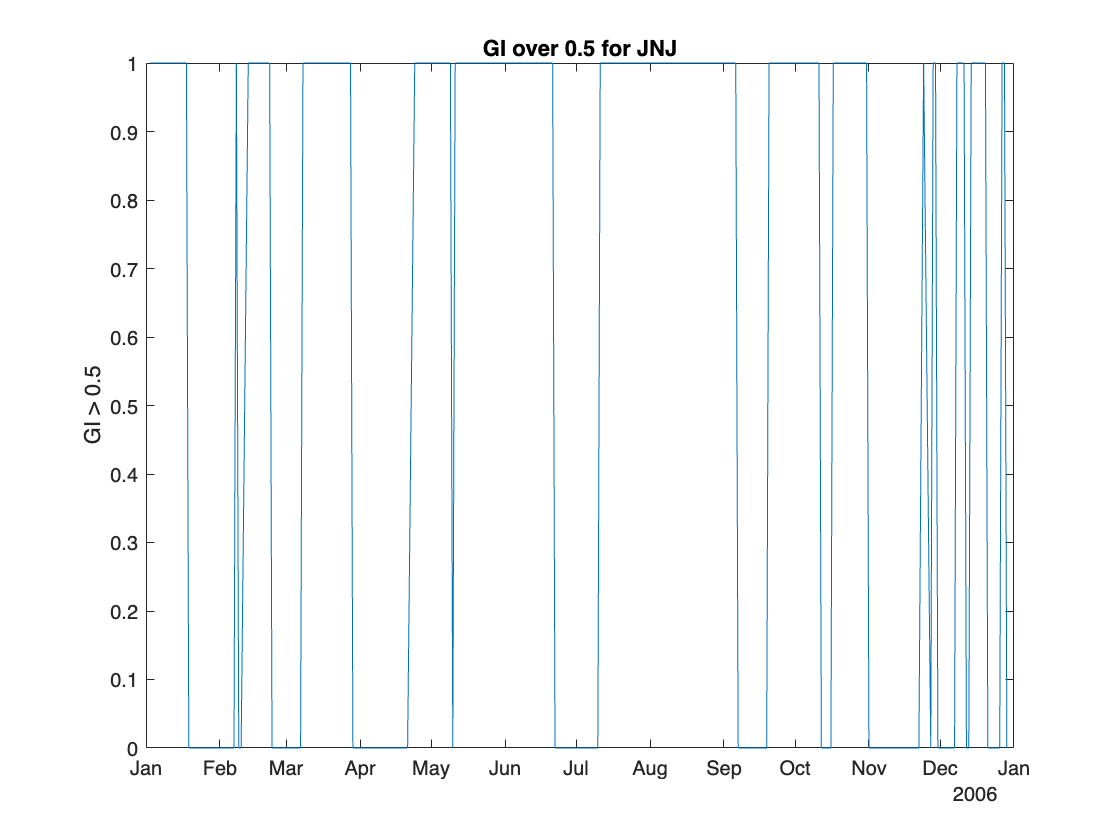


plot(GISignal.Time,GISignal.JNJ_GI)
ylabel('GI > 0.5')
title(sprintf('GI over 0.5 for JNJ'))

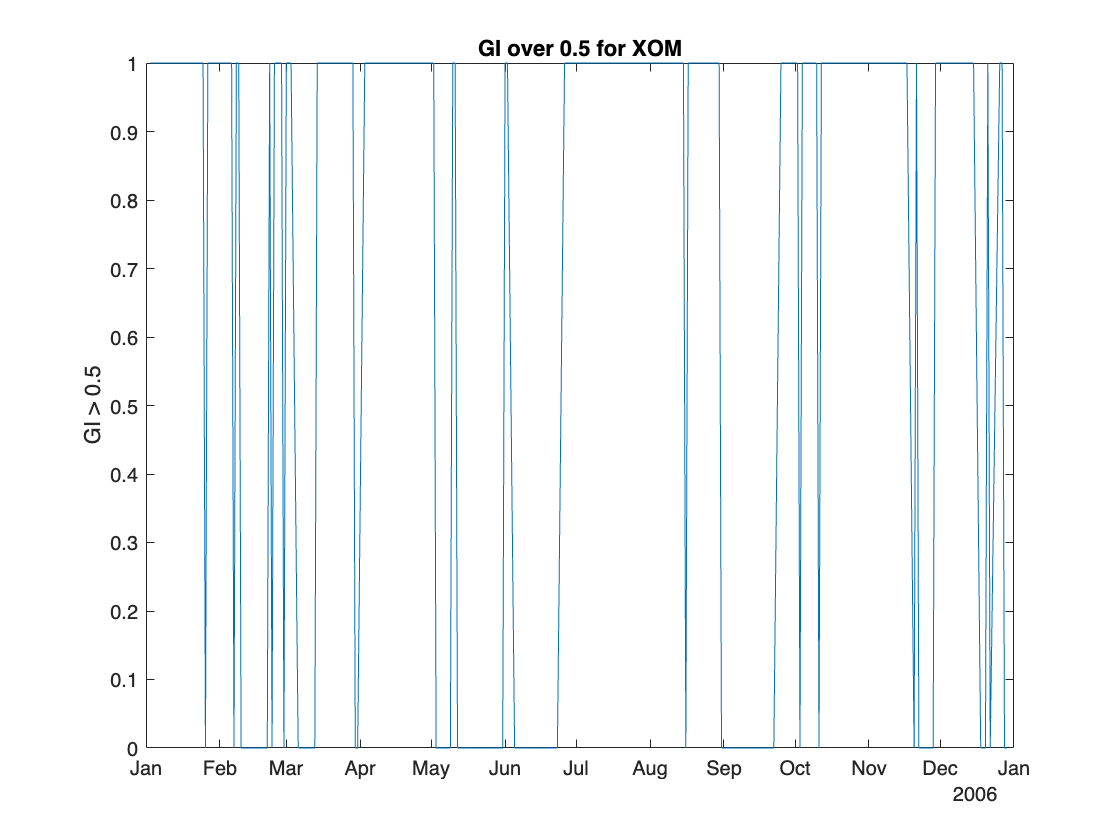


plot(GISignal.Time,GISignal.XOM_GI)
ylabel('GI > 0.5')
title(sprintf('GI over 0.5 for XOM'))

## Build the Strategies

Build the strategies for the [backtestStrategy](docid:finance_ug.object_backtest_strategy) object using the rebalance functions defined in the Local Functions section. Each strategy uses the rebalance function to make trading decisions based on the appropriate signals.

The signals require sufficient trailing data to compute the trading signals (for example, computing the `SMA20` for day *X* requires prices from the 20 days prior to day *X*). All of the trailing data is captured in the precomputed trading signals. So the actual strategies need only a 2-day lookback window to make trading decisions to evaluate when the signals cross trading thresholds.  

All strategies pay 25 basis points transaction costs on buys and sells. 

The initial weights are computed based on the signal values after 20 trading days. The backtest begins after this 20 day initialization period.

tradingCosts = 0.0025;

% Use the crossoverRebalanceFunction for both the SMA
% strategy as well as the MACD strategy.  This is because they both trade
% on their respective signals in the same way (buy when signal goes from
% 0->1, sell when signal goes from 1->0).  Build an anonymous
% function for the rebalance functions of the strategies that calls the
% shared crossoverRebalanceFcn() with the appropriate signal name string
% for each strategy.

% Each anonymous function takes the current weights (w), prices (p), 
% and signal (s) data from the backtest engine and passes it to the
% crossoverRebalanceFcn function with the signal name string.

smaInitWeights = computeInitialWeights(smaSignal(20,:));
smaRebalanceFcn = @(w,p,s) crossoverRebalanceFcn(w,p,s,smaSignalNameEnding);
smaStrategy = backtestStrategy('SMA',smaRebalanceFcn,...
    'TransactionCosts',tradingCosts,...
    'LookbackWindow',2,...
    'InitialWeights',smaInitWeights);

macdInitWeights = computeInitialWeights(macdSignal(20,:));
macdRebalanceFcn = @(w,p,s) crossoverRebalanceFcn(w,p,s,macdSignalNameEnding);
macdStrategy = backtestStrategy('MACD',macdRebalanceFcn,...
    'TransactionCosts',tradingCosts,...
    'LookbackWindow',2,...
    'InitialWeights',macdInitWeights);

% The RSI strategy uses its signal differently, buying on a 0->1
% transition and selling on a 0->-1 transition.  This logic is captured in
% the rsiRebalanceFcn function defined in the Local Functions section.
rsiInitWeights = computeInitialWeights(rsiSignal(20,:));
rsiStrategy = backtestStrategy('RSI',@rsiRebalanceFcn,...
    'TransactionCosts',tradingCosts,...
    'LookbackWindow',2,...
    'InitialWeights',rsiInitWeights);


% The GI strategy 
GIWeights = computeInitialWeights(GISignal(20,:));
GIRebalanceFcn = @(w,p,s) crossoverRebalanceFcn(w,p,s,GISignalNameEnding);
GIStrategy = backtestStrategy('GI',GIRebalanceFcn,...
    'TransactionCosts',tradingCosts,...
    'LookbackWindow',2,...
    'InitialWeights',GIWeights);

## Set Up Backtest

As a benchmark, this example also runs a simple equal-weighted strategy to determine if the trading signals are providing valuable insights into future returns of the assets. The benchmark strategy is rebalanced every four weeks.

% The equal weight strategy requires no history, so set LookbackWindow to 0.
benchmarkStrategy = backtestStrategy('Benchmark',@equalWeightFcn,...
    'TransactionCosts',tradingCosts,...
    'RebalanceFrequency',20,...
    'LookbackWindow',0);

Aggregate each of the individual signal timetables into a single backtest signal timetable.

% Combine the three signal timetables.
signalTT = timetable;
signalTT = synchronize(signalTT, smaSignal);
signalTT = synchronize(signalTT, macdSignal);
signalTT = synchronize(signalTT, rsiSignal);
signalTT = synchronize(signalTT, GISignal);

Use [backtestEngine](docid:finance_ug.object_backtest_engine) to create the backtesting engine and then use [runBacktest](docid:finance_ug.function_runbacktest) to run the backtest.  The risk-free rate earned on uninvested cash is 1% annualized.

% Put the benchmark strategy and three signal strategies into an array.
strategies = [benchmarkStrategy smaStrategy macdStrategy rsiStrategy GIStrategy];
% Create the backtesting engine.
bt = backtestEngine(strategies,'RiskFreeRate',0.01)

bt =   backtestEngine with properties:

               Strategies: [1×5 backtestStrategy]
             RiskFreeRate: 0.0100
           CashBorrowRate: 0
          RatesConvention: "Annualized"
                    Basis: 0
    InitialPortfolioValue: 10000
           DateAdjustment: "Previous"
      PayExpensesFromCash: 0
                NumAssets: []
                  Returns: []
                Positions: []
                 Turnover: []
                  BuyCost: []
                 SellCost: []
         TransactionCosts: []
                     Fees: []


## Backtest Strategies

% Start with the end of the initial weights calculation warm-up period.
startIdx = 20;

% Run the backtest.
bt = runBacktest(bt,pricesTT,signalTT,'Start',startIdx);

## Examine Backtest Results

Use [equityCurve](docid:finance_ug.function_equitycurve) to plot the strategy equity curves to visualize their performance over the backtest.

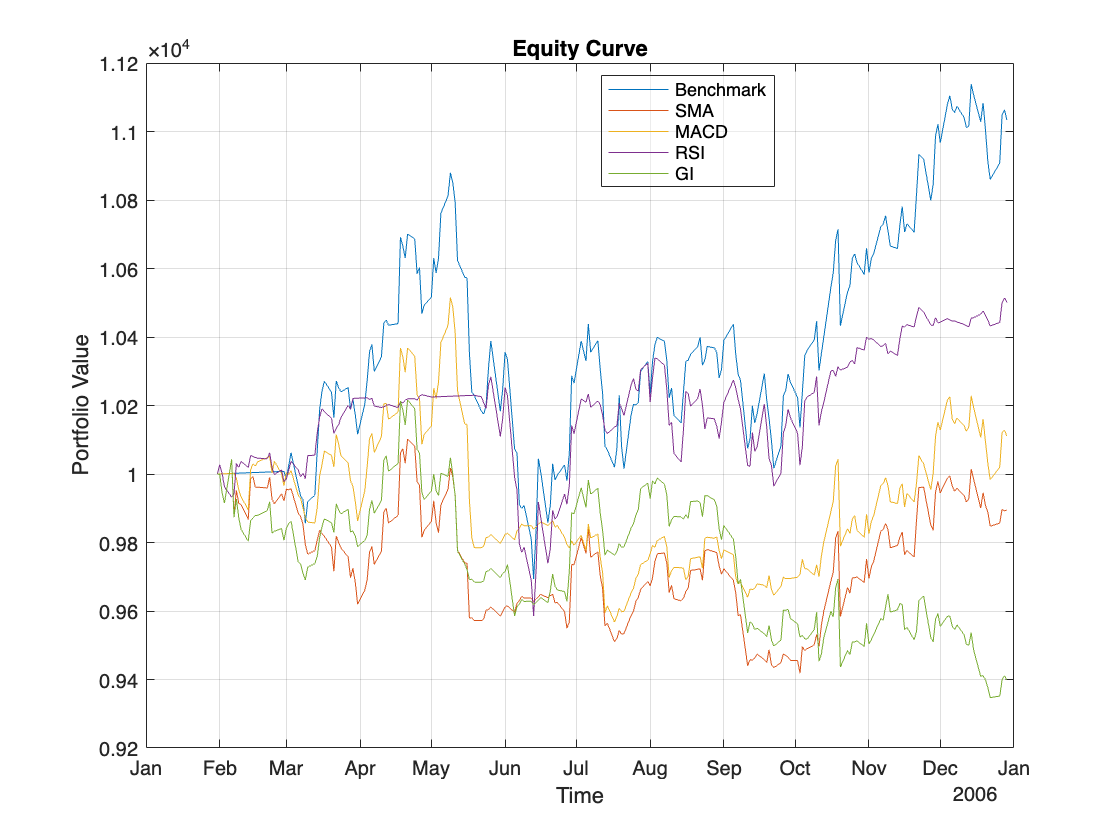

equityCurve(bt)

% Returns are in bt.Returns

You can visualize how the strategy allocations change over time using an area chart of the daily asset positions.

 To do so, use the `assetAreaPlot` helper function, defined in the Local Functions section.

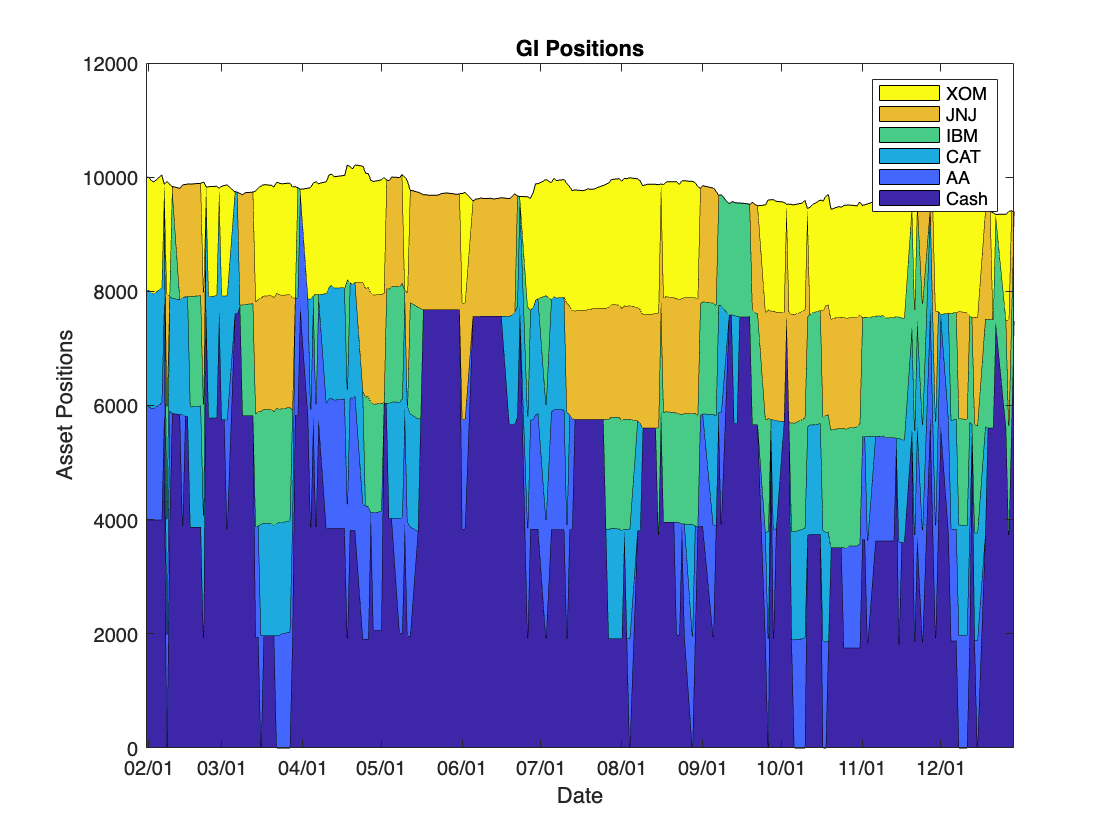


strategyName = "GI";
assetAreaPlot(bt,strategyName)

% After running your backtest, you have the backtest engine 'bt'

% Extract the returns for each strategy from the backtest results
strategyReturns = bt.Returns;

% Number of trading days in a year (assuming 252 trading days)
tradingDays = 252;

% Define the names of the strategies as a cell array
strategyNames = {'Benchmark', 'SMA', 'MACD', 'RSI', 'GI'};

% Initialize arrays to store performance metrics
numStrategies = numel(strategyNames);
meanReturnsDaily = zeros(numStrategies, 1);
stdReturnsDaily = zeros(numStrategies, 1);
meanReturnsAnnual = zeros(numStrategies, 1);
stdReturnsAnnual = zeros(numStrategies, 1);
sharpeRatiosAnnual = zeros(numStrategies, 1);
totalReturns = zeros(numStrategies, 1);
pValues = zeros(numStrategies, 1);

% Loop through each strategy to calculate performance metrics
for i = 1:numStrategies
    strategyName = strategyNames{i};  % Access the name of each strategy
    % Extract daily returns for the strategy
    returns = strategyReturns.(strategyName);
    
    % Calculate mean daily return
    meanReturnDaily = mean(returns);
    
    % Calculate standard deviation of daily returns
    stdReturnDaily = std(returns);
    
    % Annualize the mean return and standard deviation
    meanReturnAnnual = meanReturnDaily * tradingDays;
    stdReturnAnnual = stdReturnDaily * sqrt(tradingDays);
    
    % Calculate total return over the entire backtest period
    totalReturn = prod(1 + returns) - 1;
    
    % Calculate annualized Sharpe Ratio (assuming risk-free rate is zero)
    sharpeRatioAnnual = meanReturnAnnual / stdReturnAnnual;
    
    % Calculate the t-statistic for the Sharpe ratio (assuming zero risk-free rate)
    n = length(returns);  % Number of observations (daily returns)
    tStat = sharpeRatioAnnual * sqrt(n);
    
    % Calculate p-value based on the t-statistic (two-tailed test)
    pValue = 2 * (1 - tcdf(abs(tStat), n - 1));
    
    % Store the calculated metrics
    meanReturnsDaily(i) = meanReturnDaily;
    stdReturnsDaily(i) = stdReturnDaily;
    meanReturnsAnnual(i) = meanReturnAnnual;
    stdReturnsAnnual(i) = stdReturnAnnual;
    sharpeRatiosAnnual(i) = sharpeRatioAnnual;
    totalReturns(i) = totalReturn;
    pValues(i) = pValue;
end

% Create a table to display the results
resultsTable = table(strategyNames', totalReturns, meanReturnsAnnual, stdReturnsAnnual, sharpeRatiosAnnual, pValues, ...
    'VariableNames', {'Strategy', 'TotalReturn', 'MeanAnnualReturn', 'StdAnnualReturn', 'SharpeRatio', 'pValue'});

% Display the results
disp(resultsTable);

      Strategy       TotalReturn    MeanAnnualReturn    StdAnnualReturn    SharpeRatio     pValue  
    _____________    ___________    ________________    _______________    ___________    _________

    {'Benchmark'}       0.10338           0.11489           0.12307           0.93354             0
    {'SMA'      }     -0.010407        -0.0076884          0.086421         -0.088964       0.17766
    {'MACD'     }      0.011095          0.015433          0.082506           0.18705     0.0048717
    {'RSI'      }      0.050102          0.056719          0.082394           0.68839             0
    {'GI'       }     -0.060102         -0.064052          0.084433          -0.75861             0



## Local Functions

function [mu,sigma,srat,gi]=RollinWindow(Data,WSize)
% This function calculates mean, sd, sharpe ratio and GI index
% Data contains excess returns
Y=Data;
SS=size(Y);
T=SS(1,1);
F=SS(1,2);
m = WSize;       % Rolling window size
N = T - m + 1; % Number of rolling windows

% Number of parameters 
pp= 4;
% Preallocate for estimates
EstParamsMat = zeros(N,pp,F);
mu=zeros(N,F);sigma=mu;srat=mu;gi=mu;

% Estimate mean, volatility, their Sharpe ratio, GI index
for j=1:F
    for k = 1:N
        idxRW =  k:(m + k - 1); % In-sample indices
        EstParamsMat(k,1,j) = mean(Y(idxRW,j));
        EstParamsMat(k,2,j) = std(Y(idxRW,j));
        EstParamsMat(k,3,j) = mean(Y(idxRW,j)) ./std(Y(idxRW,j));    
        EstParamsMat(k,4,j) = EstParamsMat(k,3,j) ./std(Y(idxRW,j));  
    end

    % Matrix of size (T-m+1, F)

mu(:,j)=EstParamsMat(:,1,j);
sigma(:,j)=EstParamsMat(:,2,j);
srat(:,j)=EstParamsMat(:,3,j);
gi(:,j)=EstParamsMat(:,4,j);

end
end


function initial_weights = computeInitialWeights(signals)
% Compute initial weights based on most recent signal.

nAssets = size(signals,2);
final_signal = signals{end,:};
buys = final_signal == 1;
initial_weights = zeros(1,nAssets);
initial_weights(buys) = 1 / nAssets;

end

function new_weights = crossoverRebalanceFcn(current_weights, pricesTT, signalTT, signalNameEnding)
% Signal crossover rebalance function.

% Build cell array of signal names that correspond to the crossover signals.
symbols = pricesTT.Properties.VariableNames;
signalNames = cellfun(@(s) sprintf('%s%s',s,signalNameEnding), symbols, 'UniformOutput', false);

% Pull out the relevant signal data for the strategy.
crossoverSignals = signalTT(:,signalNames);

% Start with our current weights.
new_weights = current_weights;

% Sell any existing long position where the signal has turned to 0.
idx = crossoverSignals{end,:} == 0;
new_weights(idx) = 0;

% Find the new crossovers (signal changed from 0 to 1).
idx = crossoverSignals{end,:} == 1 & crossoverSignals{end-1,:} == 0;

% Bet sizing, split available capital across all remaining assets, and then
% invest only in the new positive crossover assets.  This leaves some
% proportional amount of capital uninvested for future investments into the
% zero-weight assets.
availableCapital = 1 - sum(new_weights);
uninvestedAssets = sum(new_weights == 0);
new_weights(idx) = availableCapital / uninvestedAssets;

end

function new_weights = rsiRebalanceFcn(current_weights, pricesTT, signalTT)
% Buy and sell on 1 and -1 rebalance function.

signalNameEnding = '_RSI';

% Build cell array of signal names that correspond to the crossover signals.
symbols = pricesTT.Properties.VariableNames;
signalNames = cellfun(@(s) sprintf('%s%s',s,signalNameEnding), symbols, 'UniformOutput', false);

% Pull out the relevant signal data for the strategy.
buySellSignals = signalTT(:,signalNames);

% Start with the current weights.
new_weights = current_weights;

% Sell any existing long position where the signal has turned to -1.
idx = buySellSignals{end,:} == -1;
new_weights(idx) = 0;

% Find the new buys (signal is 1 and weights are currently 0).
idx = new_weights == 0 & buySellSignals{end,:} == 1;

% Bet sizing, split available capital across all remaining assets, and then
% invest only in the new positive crossover assets.  This leaves some
% proportional amount of capital uninvested for future investments into the
% zero-weight assets.
availableCapital = 1 - sum(new_weights);
uninvestedAssets = sum(new_weights == 0);
new_weights(idx) = availableCapital / uninvestedAssets;

end

function new_weights = equalWeightFcn(current_weights,~)
% Equal-weighted portfolio allocation.

nAssets = numel(current_weights);
new_weights = ones(1,nAssets);
new_weights = new_weights / sum(new_weights);

end

function assetAreaPlot(backtester,strategyName)
% Plot the asset allocation as an area plot.

t = backtester.Positions.(strategyName).Time;
positions = backtester.Positions.(strategyName).Variables;
h = area(t,positions);
title(sprintf('%s Positions',strrep(strategyName,'_',' ')));
xlabel('Date');
ylabel('Asset Positions');
datetick('x','mm/dd','keepticks');
xlim([t(1) t(end)])
oldylim = ylim;
ylim([0 oldylim(2)]);
cm = parula(numel(h));
for i = 1:numel(h)
    set(h(i),'FaceColor',cm(i,:));
end
legend(backtester.Positions.(strategyName).Properties.VariableNames)

end


function pwgt = hrpPortfolio(T,Sigma)
% Function that computes a hierarchical risk parity portfolio. The
% algorithm first computes a risk parity portfolio for each cluster. Then,
% each cluster is assigned a weight based on a risk parity allocation of
% the covariance between the cluster's portfolios.

% Get the problem information.
nAssets = size(Sigma,1);
nClusters = max(T);

% Compute the risk parity portfolio within each cluster.
W = zeros(nAssets,nClusters);
for i = 1:nClusters
    % Identify assets in cluster i and the sub-covariance matrix.
    idx = T == i;
    tempSigma = Sigma(idx,idx);
    % Compute the risk parity portfolio of cluster i.
    W(idx,i) = riskBudgetingPortfolio(tempSigma);
end

% Compute the covariance between the risk parity portfolios of each
% cluster.
covCluster = W'*Sigma*W;

% Compute the weights of each cluster.
wBetween = riskBudgetingPortfolio(covCluster);

% Multiply the weight assigned to each cluster with its portfolio and
% assign to the corresponding assets.
pwgt = W*wBetween;

end

function idxInGroup = getLeafNodesInGroup(nodeId, link)
% getLeafNodesInGroup finds all leaf nodes for a given node id
% in a linkage matrix.

nLeaves= size(link, 1)+1;
if nodeId > nLeaves
    tempNodeIds = link(nodeId-nLeaves,1:2);
    idxInGroup = [getLeafNodesInGroup(tempNodeIds(1), link), ...
        getLeafNodesInGroup(tempNodeIds(2), link)];
else
    idxInGroup = nodeId;
end
end